# Neural and acoustic distance: congruence of networks?

Can we find any correlates between differences of vocal gestures and differences of neural activity?

There are undesirable covariate in the data: systematic other behaviors and corresponding neural response (interaction at the mesh) that correlate only with a certain type of call that by definition have acoustic features themselves really different from other type of call. Because we cannot reliably annotate these other behaviors, we cannot regress them out. So we need to focus on only one call type and see how these are covarying with neural activity.

Linear models of the type Rate ~ Acoustic feature (Gaussian, Gamma, Poisson) have several issues though:

1- We need to find a right time scale to input to the model: small binning increase the noise, but large time scale might crush the information and in particular eliminate any temporal information.

2- to over come the noise we need a large number of repetition, which we currently don't have in our dataset (need to plot here the cumulative time (duration) of vocalizations, which is the true exploitable value as compared to # calls).

Let's do a dimensionality reduction on the neural response and explore neural tuning in that reduced space.

One first idea for exploring neural tuning, to see if there is anything:

The idea here is to represent neural activity of single units into the same basis set of the PCA, then for each unit calculate the distance between pattern of activity around each vocalization and compare that with the distance of vocalizations in the acoustic space

## Representing neural responses in basis set of PCA

% Load the list of cells that show promising vocalizer patterns as
% demonstrated by the PCA/GLMM approach on average KDE over Trill and
% non-Trill calls (see explore_populationSU.mlx)
Path2AllData = '/Volumes/JulieE8T/LMCResults';
load(fullfile(Path2AllData,'explore_populationSU_data.mat'), 'ListCellsVocPCAComponent','MahalDistanceV2','VCells')
% load(fullfile(Path2AllData,'explore_populationSU_data.mat'))
% According the above mentioned notebook, 75% of these cells have a time
% resolution obtained with Coherence on Amplitude that is higher than
% 5.5ms. Let's take 5ms as the width of our Gaussian on all cells and all
% spike patterns around vocal production
TR = 10; %in ms
% also according to the above notebook, the smallest Optimal delay between
% neural response and amplitude of the vocaliztaion for optimal values of
% coherence in -74ms, so let's take neural activity only 100ms before
% vocalizations onset
Delay = 100; %in ms
% cells that have enough vocalizer Trills (>8)
ListCells = ListCellsVocPCAComponent(~isnan(MahalDistanceV2(logical(VCells(:,1)),1)));

% Obtain a large matrix of all single Trill neural activity from all
% cells NOTE:!!!! Would make sense to sample equally the cells (same number
% of vocalization for each cell, such as not to bias the basis set towards
% some particular cells? No in fact we just want the data to all be well
% represented
NC = length(ListCells);
RateNonTrills = cell(1,NC);
MeanRateNonTrills = cell(1,NC);
StimDuraMax_nonTrills = nan(NC,1); % gather the maximum duration of vocalization for each cell. The final matrix will be  hard cut at max(StimDuraMin)+100ms
NStims_nonTrills = nan(NC,1);
IndUnitsNonTrills_analysis = [];
for cc=1:NC
    % load the cell
    fprintf(1,'Cell %d/%d\n', cc, NC)
    Cell = load(ListCells{cc}, 'What', 'ExpType', 'Who', 'BioSound', 'Duration','SpikesArrivalTimes_Behav','QualitySSU', 'VocOverlap', 'AudioQuality', 'DelayBefore','DelayAfter');
    % find the correct vocalizations
    %% Various checks (Number of vocalizations in the dataset.. etc)
    if ~isfield(Cell, 'What')
        fprintf(1,'*** Problem with Cell: no what field!! ****\n')
        keyboard
        fprintf(1, '------------------Done with Calculations %s %s Self=%d in %ds-------------------\n',  FeatureName, Session, Self,toc(CellTimer));
        return
    else
        IndVoc = find(contains(Cell.What, 'VocBa') .* contains(Cell.ExpType, 'O') .* contains(Cell.Who, 'self') .* (Cell.DelayBefore>=Delay) .* (Cell.DelayAfter>=Delay));
        if length(IndVoc)<10 % focus on cell that have at least 10 non-Trills calls
            continue
        end
        IndUnitsNonTrills_analysis  = [IndUnitsNonTrills_analysis cc];
        NStims_nonTrills(cc) = length(IndVoc);
        StimDura = nan(NStims_nonTrills(cc),1);
        for sss=1:NStims_nonTrills(cc)
            StimDura(sss) = round(length(Cell.BioSound{IndVoc(sss),2}.sound) ./(Cell.BioSound{IndVoc(sss),2}.samprate)*10^3);
        end
        if any(abs(StimDura - Cell.Duration(IndVoc))>1)
            fprintf(1,'*** Problem with Cell: duration inconcistency!! ****\n')
            keyboard
            fprintf(1, '------------------Done with Calculations %s %s Self=%d in %ds-------------------\n',  FeatureName, Session, Self,toc(CellTimer));
            return
        end
    end
    StimDuraMax_nonTrills(cc) = max(StimDura);

    % calculate the Time varying Gaussian filtered spike rate for each
    % vocalization and also the average spike rate during the vocalization
    % starting -100ms before stim on set and stopping at stim offset
    % neural response is a vector that compile for each stim all spike counts starting
    % at -100ms (Delay) before stim onset and stop at 2000ms after
    % stim onset with a time resolution TR
    [YPerStim, YPerStimt, MeanRateNonTrills{cc}] = get_y(Cell.SpikesArrivalTimes_Behav(IndVoc), Cell.Duration(IndVoc),[-Delay 2000],TR);
    RateNonTrills{cc} = YPerStim';
end

Cell 1/62
Cell 2/62
Cell 3/62
Cell 4/62
Cell 5/62
Cell 6/62
Cell 7/62
Cell 8/62
Cell 9/62
Cell 10/62
Cell 11/62
Cell 12/62
Cell 13/62
Cell 14/62
Cell 15/62
Cell 16/62
Cell 17/62
Cell 18/62
Cell 19/62
Cell 20/62
Cell 21/62
Cell 22/62
Cell 23/62
Cell 24/62
Cell 25/62
Cell 26/62
Cell 27/62
Cell 28/62
Cell 29/62
Cell 30/62
Cell 31/62
Cell 32/62
Cell 33/62
Cell 34/62
Cell 35/62
Cell 36/62
Cell 37/62
Cell 38/62
Cell 39/62
Cell 40/62
Cell 41/62
Cell 42/62
Cell 43/62
Cell 44/62
Cell 45/62
Cell 46/62
Cell 47/62
Cell 48/62
Cell 49/62
Cell 50/62
Cell 51/62
Cell 52/62
Cell 53/62
Cell 54/62
Cell 55/62
Cell 56/62
Cell 57/62
Cell 58/62
Cell 59/62
Cell 60/62
Cell 61/62
Cell 62/62


save(fullfile(Path2AllData,'explore_populationSU_data.mat'), 'RateNonTrills', 'MeanRateNonTrills','NStims_nonTrills','IndUnitsNonTrills_analysis', '-append')

NC = length(IndUnitsNonTrills_analysis);
RateNonTrills_mat = [RateNonTrills{IndUnitsNonTrills_analysis}]';
StimDuraMax_nonTrills = StimDuraMax_nonTrills(IndUnitsNonTrills_analysis);
MeanRateNonTrills = MeanRateNonTrills(IndUnitsNonTrills_analysis);
NStims_nonTrills = NStims_nonTrills(IndUnitsNonTrills_analysis);
% cut the matrix at mean(Max duration of vocalization) + Delay/2
StimDuraOpt_NT = round(nanmean(StimDuraMax_nonTrills)/10)*10;
RateNonTrills_mat = RateNonTrills_mat(:, 1:StimDuraOpt_NT+1.5*Delay);
% substract the time varying mean
RateNonTrills_centered = RateNonTrills_mat - mean(RateNonTrills_mat);
[PC_NonTrill,Score_NonTrill,~, ~, VarExpl_NonTrill,~] = pca(RateNonTrills_mat);

% Run a PCA per cell
PC_per_cell_NT = cell(NC,1);
Score_per_cell_NT = cell(NC,1);
VarExpl_per_cell_NT = cell(NC,1);
RateNonTrills_mat_per_cell = cell(NC,1);
NPC_per_cell_NT = nan(NC,1);
for cc=1:NC
    if NStims_nonTrills(cc)<10 % not enough data to perform that analysis
        continue
    end
    RateNonTrills_mat_per_cell{cc} = RateNonTrills{IndUnitsNonTrills_analysis(cc)}(1:StimDuraOpt_NT+1.5*Delay,:)';
    [PC_per_cell_NT{cc},Score_per_cell_NT{cc},~, ~, VarExpl_per_cell_NT{cc},~] = pca(RateNonTrills_mat_per_cell{cc});
    NPC_per_cell_NT(cc)=find(cumsum(VarExpl_per_cell_NT{cc})>90,1);
end

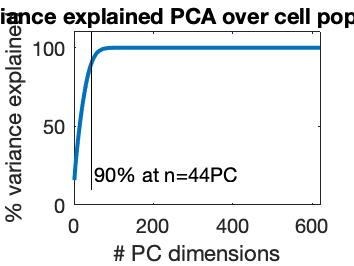

% Plot the variance explained
figure
plot(cumsum(VarExpl_NonTrill), 'LineWidth',2)
xlabel('# PC dimensions')
ylabel('% variance explained')
hold on
vline(find(cumsum(VarExpl_NonTrill)>90,1), '-k',sprintf('90%% at n=%dPC', find(cumsum(VarExpl_NonTrill)>90,1)))
hold off
title('Variance explained PCA over cell population')

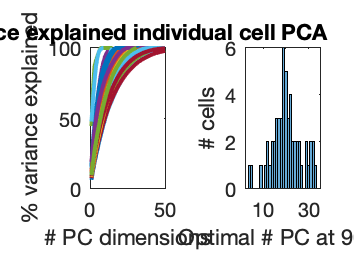

% Plot the variance explained for individual cells PCA
t=tiledlayout(1,2);
CumsumVE = nan(NC,20);
nexttile
for cc=1:NC
    if ~isempty(VarExpl_per_cell_NT{cc})
        plot(cumsum(VarExpl_per_cell_NT{cc}), 'LineWidth',2)
        xlabel('# PC dimensions')
        ylabel('% variance explained')
        hold on
        VarMax = min(length(VarExpl_per_cell_NT{cc}),20);
        CumsumVE(cc,1:VarMax) = cumsum(VarExpl_per_cell_NT{cc}(1:VarMax));
    end
end
xlim([0 50])
title('Variance explained individual cell PCA')
hold off
nexttile
histogram(NPC_per_cell_NT)
xlabel('Optimal # PC at 90%')
ylabel('# cells')

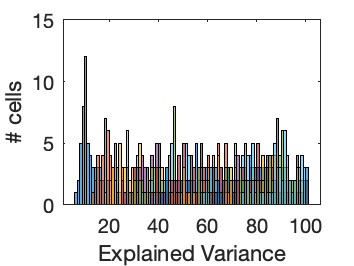


figure
for pp=1:20
    histogram(CumsumVE(:,pp),'BinWidth',1, 'DisplayName', sprintf('%d',pp))
    hold on
end
xlabel('Explained Variance')
ylabel('# cells')
hold off

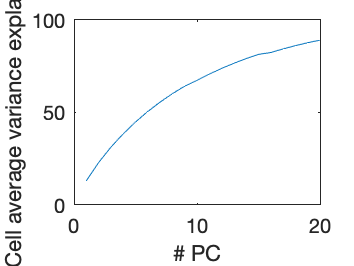


figure
plot(nanmean(CumsumVE))
xlabel('# PC')
ylabel('Cell average variance explained')

% Plot the average time varying rate
figure
shadedErrorBar([],mean(RateNonTrills_mat), std(RateNonTrills_mat)*(size(RateNonTrills_mat,1))^-0.5, {'k-','LineWidth',2});ylabel('Mean spike rate');xlabel('Time (s)');xticks(0:100:round(StimDuraOpt_NT+1.5*Delay));xticklabels(-100:100:round(StimDuraOpt_NT+Delay/2));title('Average spike rate during non-Trills over all vocalizer cells')
hold off


% Plot the first PC shapes
plot(PC_NonTrill(:,1), 'LineWidth',2);hold on;plot(PC_NonTrill(:,2), 'LineWidth',2);plot(PC_NonTrill(:,3), 'LineWidth',2);plot(PC_NonTrill(:,4), 'LineWidth',2);plot(PC_NonTrill(:,5), 'LineWidth',2);plot(PC_NonTrill(:,6), 'LineWidth',2);plot(PC_NonTrill(:,7), 'LineWidth',2);plot(PC_NonTrill(:,8), 'LineWidth',2);plot(PC_NonTrill(:,9), 'LineWidth',2);plot(PC_NonTrill(:,10), 'LineWidth',2);legend('PC1', 'PC2','PC3', 'PC4', 'PC5', 'PC6','PC7','PC8','PC9','PC10', 'Location', 'EastOutside'); ylabel('PCA coefficients');xlabel('Time (s)');xticks(0:100:round(StimDuraOpt_NT+1.5*Delay));xticklabels(-100:100:round(StimDuraOpt_NT+Delay/2));title('PCA basis set of spike rate on non-Trill')
hold off

% plot all cells in the PC space
CellID = cell(1,NC);
for cc=1:NC
    CellID{cc} = cc.*ones(1,NStims_nonTrills(cc));
end
CellID = [CellID{:}]';
gscatter(Score_NonTrill(:,1), Score_NonTrill(:,2), CellID)
xlabel('PC1')
ylabel('PC2')

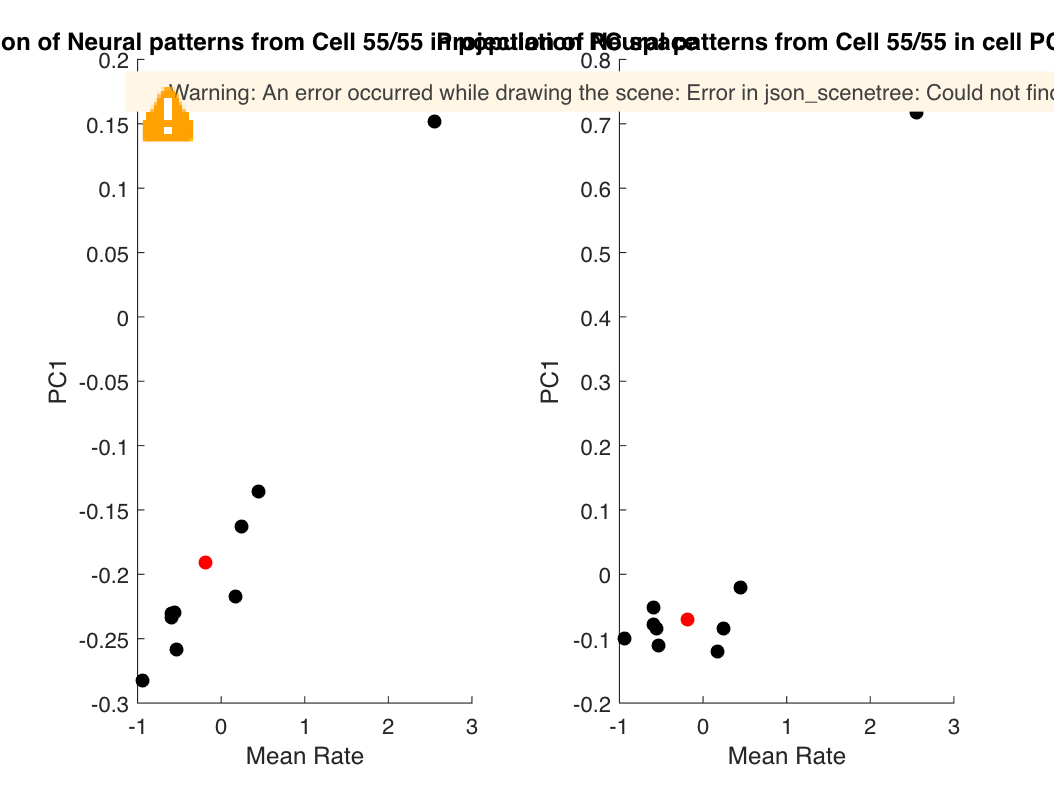

% Obtain the matrix of neural distance for each cell
% calculate for each cell the centroid of the cloud of responses and find
% the neural pattern (the instance) that is closer to the centroid. It will
% be used as a reference point to calculate distance to other instances
NPC_NT = find(cumsum(VarExpl_NonTrill)>90,1);
NeuralVectorDistance_NT = cell(NC,2); % first column: PCA over all responses from all cells; second column: PCA per cell
NeuralMatrixDistance_NT = cell(NC,2);% first column: PCA over all responses from all cells; second column: PCA per cell
for cc=1:NC
    % Using Cellpopulation PCA
    % Find the rows in Score that correspond to that cell
    if cc~=1
        Row1 = cumsum(NStims_nonTrills(1:cc-1));
    elseif cc==1
        Row1=0;
    end
    Score_local = Score_NonTrill(Row1(end)+(1:NStims_nonTrills(cc)),1:min(NPC_NT, floor(NStims_nonTrills(cc)/10)));
    % Calculate the centroid of the cloud of observations
    Centroid = mean([zscore(MeanRateNonTrills{cc}) Score_local]);
    % Find the observation that is closest to the centroid in Euclidean
    % distance, it will be used as a reference to calculate all other
    % distances
    D = squareform(pdist([zscore(MeanRateNonTrills{cc}) Score_local; Centroid], 'seuclidean'));
    DCentroid = D(NStims_nonTrills(cc)+1,:);
    CentralInstance = find(DCentroid(1:end-1) == min(DCentroid(1:end-1)));
    % Calculate the euclidean distance of all other points to the
    % reference point
    NeuralVectorDistance_NT{cc,1} = D(CentralInstance(1), 1:end-1);
    NeuralMatrixDistance_NT{cc,1} = D(1:(end-1), 1:end-1);
    
    % Using individual cell PCA
    Score_local2 = Score_per_cell_NT{cc}(:,1:min(NPC_per_cell_NT(cc), floor(NStims_nonTrills(cc)/10)));
    % Calculate the centroid of the cloud of observations
    Centroid = mean([zscore(MeanRateNonTrills{cc}) Score_local2]);
    % Find the observation that is closest to the centroid in Euclidean
    % distance, it will be used as a reference to calculate all other
    % distances
    D = squareform(pdist([zscore(MeanRateNonTrills{cc}) Score_local2; Centroid], 'seuclidean'));
    DCentroid = D(NStims_nonTrills(cc)+1,:);
    CentralInstance2 = find(DCentroid(1:end-1) == min(DCentroid(1:end-1)));
    % Calculate the euclidean distance of all other points to the
    % reference point
    NeuralVectorDistance_NT{cc,2} = D(CentralInstance2(1), 1:end-1);
    NeuralMatrixDistance_NT{cc,2} = D(1:(end-1), 1:end-1);

    % plot
    Col = zeros(NStims_nonTrills(cc),3);
    Col(CentralInstance(1),:) = [1 0 0];
    tiledlayout(1,2)
    nexttile
    scatter(zscore(MeanRateNonTrills{cc}),Score_local(:,1),40,Col, 'filled')
    xlabel('Mean Rate')
    ylabel('PC1')
    title(sprintf('Projection of Neural patterns from Cell %d/%d in population PC space', cc, NC))
    nexttile
    Col = zeros(NStims_nonTrills(cc),3);
    Col(CentralInstance2(1),:) = [1 0 0];
    scatter(zscore(MeanRateNonTrills{cc}),Score_local2(:,1),40,Col, 'filled')
    xlabel('Mean Rate')
    ylabel('PC1')
    title(sprintf('Projection of Neural patterns from Cell %d/%d in cell PC space', cc, NC))
%     pause()
end

save(fullfile(Path2AllData,'explore_populationSU_data.mat'), 'NeuralMatrixDistance_NT','NeuralVectorDistance_NT','NPC_NT','NPC_per_cell_NT', 'Score_NonTrill', 'Score_per_cell_NT','PC_per_cell_NT','StimDuraMax_nonTrills', '-append')

## Representing Vocalizations in an acoustic basis set

Let's represent Trills iteratively by PCA on a given time varying acoustic feature, substracting the time varying mean acoustic feature

NC = length(IndUnitsNonTrills_analysis);
% Import Biosound library
py.importlib.import_module('soundsig');

% Obtain a large matrix of all single non-Trill time varying pitch, amplitude, saliency etc...
NonTrills_fund = cell(1,NC);
NonTrills_sal = cell(1,NC);
NonTrills_amp = cell(1,NC);
NonTrills_specMean = cell(1,NC);
NonTrills_formDisp = cell(1,NC);
NonTrills_mps = cell(1,NC);
NonTrills_spectroPiezo = cell(1,NC);
NonTrills_spectroPiezoto = cell(1,NC);
NonTrills_spectroPiezofo = cell(1,NC);
NonTrills_spectroMic = cell(1,NC);
NonTrills_spectroMicto = cell(1,NC);
NonTrills_spectroMicfo = cell(1,NC);
SoundSpeed = 350;
Span=9;% Span is an unevennumber. smooth has a default span of 5 points = 5ms However end points are unchanged...
for cc=1:NC
    % load the cell
    fprintf(1,'Cell %d/%d\n', cc, NC)
    Cell = load(ListCells{IndUnitsNonTrills_analysis(cc)}, 'What', 'ExpType', 'Who', 'BioSound', 'Duration','SpikesArrivalTimes_Behav','QualitySSU', 'VocOverlap', 'AudioQuality', 'DelayBefore','DelayAfter');
    % find the correct vocalizations
    %% Various checks (Number of vocalizations in the dataset.. etc)
    if ~isfield(Cell, 'What')
        fprintf(1,'*** Problem with Cell: no what field!! ****\n')
        keyboard
        fprintf(1, '------------------Done with Calculations %s %s Self=%d in %ds-------------------\n',  FeatureName, Session, Self,toc(CellTimer));
        return
    else
        IndVoc = find(contains(Cell.What, 'VocBa') .* contains(Cell.ExpType, 'O') .* contains(Cell.Who, 'self') .* (Cell.DelayBefore>=Delay) .* (Cell.DelayAfter>=Delay));
        
    end
    
    % initialize the matrix of acoustic values with zeros
    NonTrills_fund{cc} = zeros(max(StimDuraMax_nonTrills),length(IndVoc));
    NonTrills_sal{cc} = zeros(max(StimDuraMax_nonTrills),length(IndVoc));
    NonTrills_amp{cc} = zeros(max(StimDuraMax_nonTrills),length(IndVoc));
    NonTrills_specMean{cc} = zeros(max(StimDuraMax_nonTrills),length(IndVoc));
    NonTrills_formDisp{cc} = zeros(max(StimDuraMax_nonTrills),length(IndVoc));
    NonTrills_mps{cc} = cell(1, length(IndVoc));
    NonTrills_spectroPiezo{cc} = cell(1, length(IndVoc));
    NonTrills_spectroPiezoto{cc} = cell(1, length(IndVoc));
    NonTrills_spectroPiezofo{cc} = cell(1, length(IndVoc));
    NonTrills_spectroMic{cc} = cell(1, length(IndVoc));
    NonTrills_spectroMicto{cc} = cell(1, length(IndVoc));
    NonTrills_spectroMicfo{cc} = cell(1, length(IndVoc));

    
    % collect the Time varying smoothed acoustic features for each
    % vocalization
    for Nstim = 1:NStims_nonTrills(cc)
        StimDur = length(Cell.BioSound{IndVoc(Nstim),1}.amp);
        if ~isempty(Cell.BioSound{IndVoc(Nstim),2}.f0)
            NonTrills_fund{cc}(1:StimDur,Nstim) = mysmooth(Cell.BioSound{IndVoc(Nstim),2}.f0, Span);
            F1 = double(Cell.BioSound{IndVoc(Nstim),1}.F1);
            F2 = double(Cell.BioSound{IndVoc(Nstim),1}.F2);
            NonTrills_formDisp{cc}(1:StimDur,Nstim) = mysmooth(SoundSpeed./(2*(F2 - F1))*1000, Span);
        end
        NonTrills_sal{cc}(1:StimDur,Nstim) = mysmooth(Cell.BioSound{IndVoc(Nstim),1}.sal, Span);
        NonTrills_amp{cc}(1:StimDur,Nstim) = mysmooth(Cell.BioSound{IndVoc(Nstim),1}.amp, Span);
        NonTrills_specMean{cc}(1:StimDur,Nstim) = mysmooth(Cell.BioSound{IndVoc(Nstim),1}.SpectralMean, Span);
        
        % Calculate the MPS and save it
        FS = Cell.BioSound{IndVoc(Nstim),1}.samprate;
        Y = zeros(max(StimDuraMax_nonTrills)*FS/10^3,1);
        Sound = Cell.BioSound{IndVoc(Nstim),1}.sound;
        Y(1:length(Sound)) = Sound;
        [MPS, Wf, Wt] = mps_calc(Y, FS);
        if Nstim>1
            if any(NonTrills_wf ~= Wf)
                return
            end
            if any(NonTrills_wt ~= Wt)
                return
            end
        end
        NonTrills_wt = Wt;
        NonTrills_wf = Wf;
        NonTrills_mps{cc}{Nstim}= reshape(MPS, numel(MPS),1);
        NonTrills_spectroPiezo{cc}{Nstim}= Cell.BioSound{IndVoc(Nstim),2}.spectro;
        NonTrills_spectroPiezoto{cc}{Nstim}= Cell.BioSound{IndVoc(Nstim),2}.to;
        NonTrills_spectroPiezofo{cc}{Nstim}= Cell.BioSound{IndVoc(Nstim),2}.fo;
        NonTrills_spectroMic{cc}{Nstim}= Cell.BioSound{IndVoc(Nstim),1}.spectro;
        NonTrills_spectroMicto{cc}{Nstim}= Cell.BioSound{IndVoc(Nstim),1}.to;
        NonTrills_spectroMicfo{cc}{Nstim}= Cell.BioSound{IndVoc(Nstim),1}.fo;
    end
end

Cell 1/55
Cell 2/55
Cell 3/55
Cell 4/55
Cell 5/55
Cell 6/55
Cell 7/55
Cell 8/55
Cell 9/55
Cell 10/55
Cell 11/55
Cell 12/55
Cell 13/55
Cell 14/55
Cell 15/55
Cell 16/55
Cell 17/55
Cell 18/55
Cell 19/55
Cell 20/55
Cell 21/55
Cell 22/55
Cell 23/55
Cell 24/55
Cell 25/55
Cell 26/55
Cell 27/55
Cell 28/55
Cell 29/55
Cell 30/55
Cell 31/55
Cell 32/55
Cell 33/55
Cell 34/55
Cell 35/55
Cell 36/55
Cell 37/55
Cell 38/55
Cell 39/55
Cell 40/55
Cell 41/55
Cell 42/55
Cell 43/55
Cell 44/55
Cell 45/55
Cell 46/55
Cell 47/55
Cell 48/55
Cell 49/55
Cell 50/55
Cell 51/55
Cell 52/55
Cell 53/55
Cell 54/55
Cell 55/55


save(fullfile(Path2AllData,'explore_populationSU_data.mat'), 'NonTrills_fund','NonTrills_amp','NonTrills_formDisp','NonTrills_mps', 'NonTrills_sal', 'NonTrills_specMean','NonTrills_wt', 'NonTrills_wf','NonTrills_spectroPiezo', 'NonTrills_spectroPiezoto', 'NonTrills_spectroPiezofo','NonTrills_spectroMic', 'NonTrills_spectroMicto', 'NonTrills_spectroMicfo', '-append')

NonTrills_fund_mat = [NonTrills_fund{:}]';
NonTrills_sal_mat = [NonTrills_sal{:}]';
NonTrills_amp_mat = [NonTrills_amp{:}]';
NonTrills_specMean_mat = [NonTrills_specMean{:}]';
NonTrills_formDisp_mat = [NonTrills_formDisp{:}]';
NonTrills_mps_mat = [NonTrills_mps{:}];
NonTrills_mps_mat = [NonTrills_mps_mat{:}]';

% replace nan values by 0
NonTrills_fund_mat(isnan(NonTrills_fund_mat)) = 0;
NonTrills_sal_mat(isnan(NonTrills_sal_mat)) = 0;
NonTrills_amp_mat(isnan(NonTrills_amp_mat)) = 0;
NonTrills_specMean_mat(isnan(NonTrills_specMean_mat)) = 0;
NonTrills_formDisp_mat(isnan(NonTrills_formDisp_mat)) = 0;
% there should not be any nan values in mps
if any(isnan(NonTrills_mps_mat))
    return
end

% substract the time varying mean
NonTrills_fund_centered = NonTrills_fund_mat - mean(NonTrills_fund_mat);
NonTrills_sal_centered = NonTrills_sal_mat - mean(NonTrills_sal_mat);
NonTrills_amp_centered = NonTrills_amp_mat - mean(NonTrills_amp_mat);
NonTrills_specMean_centered = NonTrills_specMean_mat - mean(NonTrills_specMean_mat);
NonTrills_formDisp_centered = NonTrills_formDisp_mat - mean(NonTrills_formDisp_mat);
NonTrills_mps_centered = NonTrills_mps_mat - mean(NonTrills_mps_mat);

% Calculate independant PCA for each (by default pca center the data)
[PC_fund_NT,Score_fund_NT,~, ~, VarExpl_fund_NT,~] = pca(NonTrills_fund_mat);

[PC_sal_NT,Score_sal_NT,~, ~, VarExpl_sal_NT,~] = pca(NonTrills_sal_mat);

[PC_amp_NT,Score_amp_NT,~, ~, VarExpl_amp_NT,~] = pca(NonTrills_amp_mat);

[PC_specMean_NT,Score_specMean_NT,~, ~, VarExpl_specMean_NT,~] = pca(NonTrills_specMean_mat);

[PC_formDisp_NT,Score_formDisp_NT,~, ~, VarExpl_formDisp_NT,~] = pca(NonTrills_formDisp_mat);

[PC_mps_NT,Score_mps_NT,~, ~, VarExpl_mps_NT,~] = pca(NonTrills_mps_centered);

% Indices of non-null fundamental vocalizations
IndNonNullVoc = find(sum(NonTrills_fund_mat));
% Plot the average vocalization
HalfSpan = (Span-1)/2;
% Plot the pitch saliency vs amplitude on microphone
figure()
subplot(4,1,1)
hold off
Saliency = mean(NonTrills_sal_mat);
Amplitude = mean(NonTrills_amp_mat);
TimeSound = 1:size(NonTrills_sal_mat,2);
TimeSound = TimeSound./max(TimeSound);
cmap = colormap('jet');
ncolors = length(cmap);
nx = length(Saliency);

for ii=HalfSpan:nx-HalfSpan
    segcolor = cmap(fix((TimeSound(ii)+TimeSound(ii+1))*ncolors./2)+1,:);
    plot([Saliency(ii), Saliency(ii+1)], [Amplitude(ii), Amplitude(ii+1)], "Color",segcolor, "LineWidth",2);
    hold on;
end
set(gca,'XLim',[0 1]);
xlabel(sprintf('Pitch Saliency %.1f', mean(Saliency)))
ylabel('Amplitude')
hold off

% Plot the difference of formants (Mic data) vs sound amplitude (Mic
% Data)
subplot(4,1,2)
hold off
FormantDisp = mean(NonTrills_formDisp_mat(IndNonNullVoc,:));
nx = length(FormantDisp);
Amplitude2 = mean(NonTrills_amp_mat(IndNonNullVoc,:));

for ii=HalfSpan:nx-HalfSpan
    segcolor = cmap(fix((TimeSound(ii)+TimeSound(ii+1))*ncolors./2)+1,:);
    plot([FormantDisp(ii), FormantDisp(ii+1)], [Amplitude2(ii), Amplitude2(ii+1)], "Color",segcolor, "LineWidth",2);
    hold on;
end
set(gca,'XLim',[10 150])
xlabel('1/Formant disp (vocal tract length (mm))')
ylabel('Amplitude')
hold off

% Plot the amplitude (Mic data) vs fundamental (Piezo
% Data)
subplot(4,1,3)
hold off
SoundFund = mean(NonTrills_fund_mat(IndNonNullVoc,:));
if ~isempty(SoundFund)
    for ii=HalfSpan:nx-HalfSpan
        segcolor = cmap(fix((TimeSound(ii)+TimeSound(ii+1))*ncolors./2)+1,:);
        plot([SoundFund(ii), SoundFund(ii+1)], [Amplitude2(ii), Amplitude2(ii+1)], "Color",segcolor, "LineWidth",2);
        hold on;
    end
    ylabel('Amplitude')
    xlabel(sprintf('Fundamental (Hz), %.1f Hz', mean(SoundFund)))
    set(gca,'XLim',[100 3000])
end
hold off

% Plot the Amplitude (Mic data) vs SpectralMean (Mic
% Data)
subplot(4,1,4)
hold off
SoundSpecMean = mean(NonTrills_specMean_mat);
if ~isempty(SoundSpecMean)
    for ii=HalfSpan:nx-HalfSpan
        segcolor = cmap(fix((TimeSound(ii)+TimeSound(ii+1))*ncolors./2)+1,:);
        plot([SoundSpecMean(ii), SoundSpecMean(ii+1)], [Amplitude(ii), Amplitude(ii+1)], "Color",segcolor, "LineWidth",2);
        hold on;
    end
    ylabel('Amplitude')
    xlabel(sprintf('Spectral Mean (Hz), %.1f Hz', mean(SoundSpecMean)))
%     set(gca,'XLim',[25000 30000])
end
hold off

% Indices of non-null fundamental vocalizations
IndNonNullVoc = find(sum(NonTrills_fund_mat));
% Plot the average vocalization
HalfSpan = (Span-1)/2;
% Plot the amplitude on microphone
figure()
subplot(5,1,1)
Amplitude = mean(NonTrills_amp_mat);
TimeSound = 1:size(NonTrills_sal_mat,2);
shadedErrorBar(TimeSound,Amplitude, 2*std(NonTrills_amp_mat)./(size(NonTrills_amp_mat,1))^0.5,{"LineWidth",2});
ylabel(sprintf('Amplitude %.1f', mean(Amplitude)))
xlabel('Time (ms)')

% Plot the pitch saliency vs amplitude on microphone
subplot(5,1,2)
Saliency = mean(NonTrills_sal_mat);
shadedErrorBar(TimeSound,Saliency, 2*std(NonTrills_sal_mat)./(size(NonTrills_sal_mat,1))^0.5,{"LineWidth",2});
ylabel(sprintf('Saliency %.1f', mean(Saliency)))
xlabel('Time (ms)')

% Plot the difference of formants (Mic data)
subplot(5,1,3)
hold off
FormantDisp = mean(NonTrills_formDisp_mat(IndNonNullVoc,:));
shadedErrorBar(TimeSound,FormantDisp,2*std(NonTrills_formDisp_mat(IndNonNullVoc,:))./length(IndNonNullVoc)^0.5,{"LineWidth",2});
ylabel('1/Formant disp (vocal tract length (mm))')
xlabel('Time (ms)')

% fundamental (Piezo
% Data)
subplot(5,1,4)
SoundFund = mean(NonTrills_fund_mat(IndNonNullVoc,:));
if ~isempty(SoundFund)
    shadedErrorBar(TimeSound, SoundFund, 2*std(NonTrills_fund_mat(IndNonNullVoc,:))./length(IndNonNullVoc)^0.5, { "LineWidth",2});
    xlabel('Time (ms)')
    ylabel(sprintf('Fundamental (Hz), %.1f Hz', mean(SoundFund)))
    set(gca,'YLim',[100 3000])
end

% Plot SpectralMean (Mic
% Data)
subplot(5,1,5)
SoundSpecMean = mean(NonTrills_specMean_mat);
if ~isempty(SoundSpecMean)
    shadedErrorBar(TimeSound,SoundSpecMean, 2*std(NonTrills_specMean_mat)./length(IndNonNullVoc)^0.5, {"LineWidth",2});
    xlabel('Time (ms)')
    ylabel(sprintf('Spectral Mean (Hz), %.1f Hz', mean(SoundSpecMean)))
%     set(gca,'XLim',[25000 30000])
end

% plot the average and the STD mps
DBNOISE = 60;
figure
tiledlayout(2,2)
nexttile
MeanMPS = reshape(mean(NonTrills_mps_mat),length(NonTrills_wf), length(NonTrills_wt));
plot_mps(MeanMPS, NonTrills_wf, NonTrills_wt, DBNOISE);
title(' Mean MPS for Non-Trills')

nexttile
STDMPS = reshape(std(NonTrills_mps_mat),length(NonTrills_wf), length(NonTrills_wt));
plot_mps(STDMPS, NonTrills_wf, NonTrills_wt, DBNOISE);
title(' STD MPS for Non-Trills')

nexttile
VarMPS = STDMPS./MeanMPS;
plot_mps(VarMPS, NonTrills_wf, NonTrills_wt, DBNOISE,0);
title(' Coeff Var MPS for NonTrills')

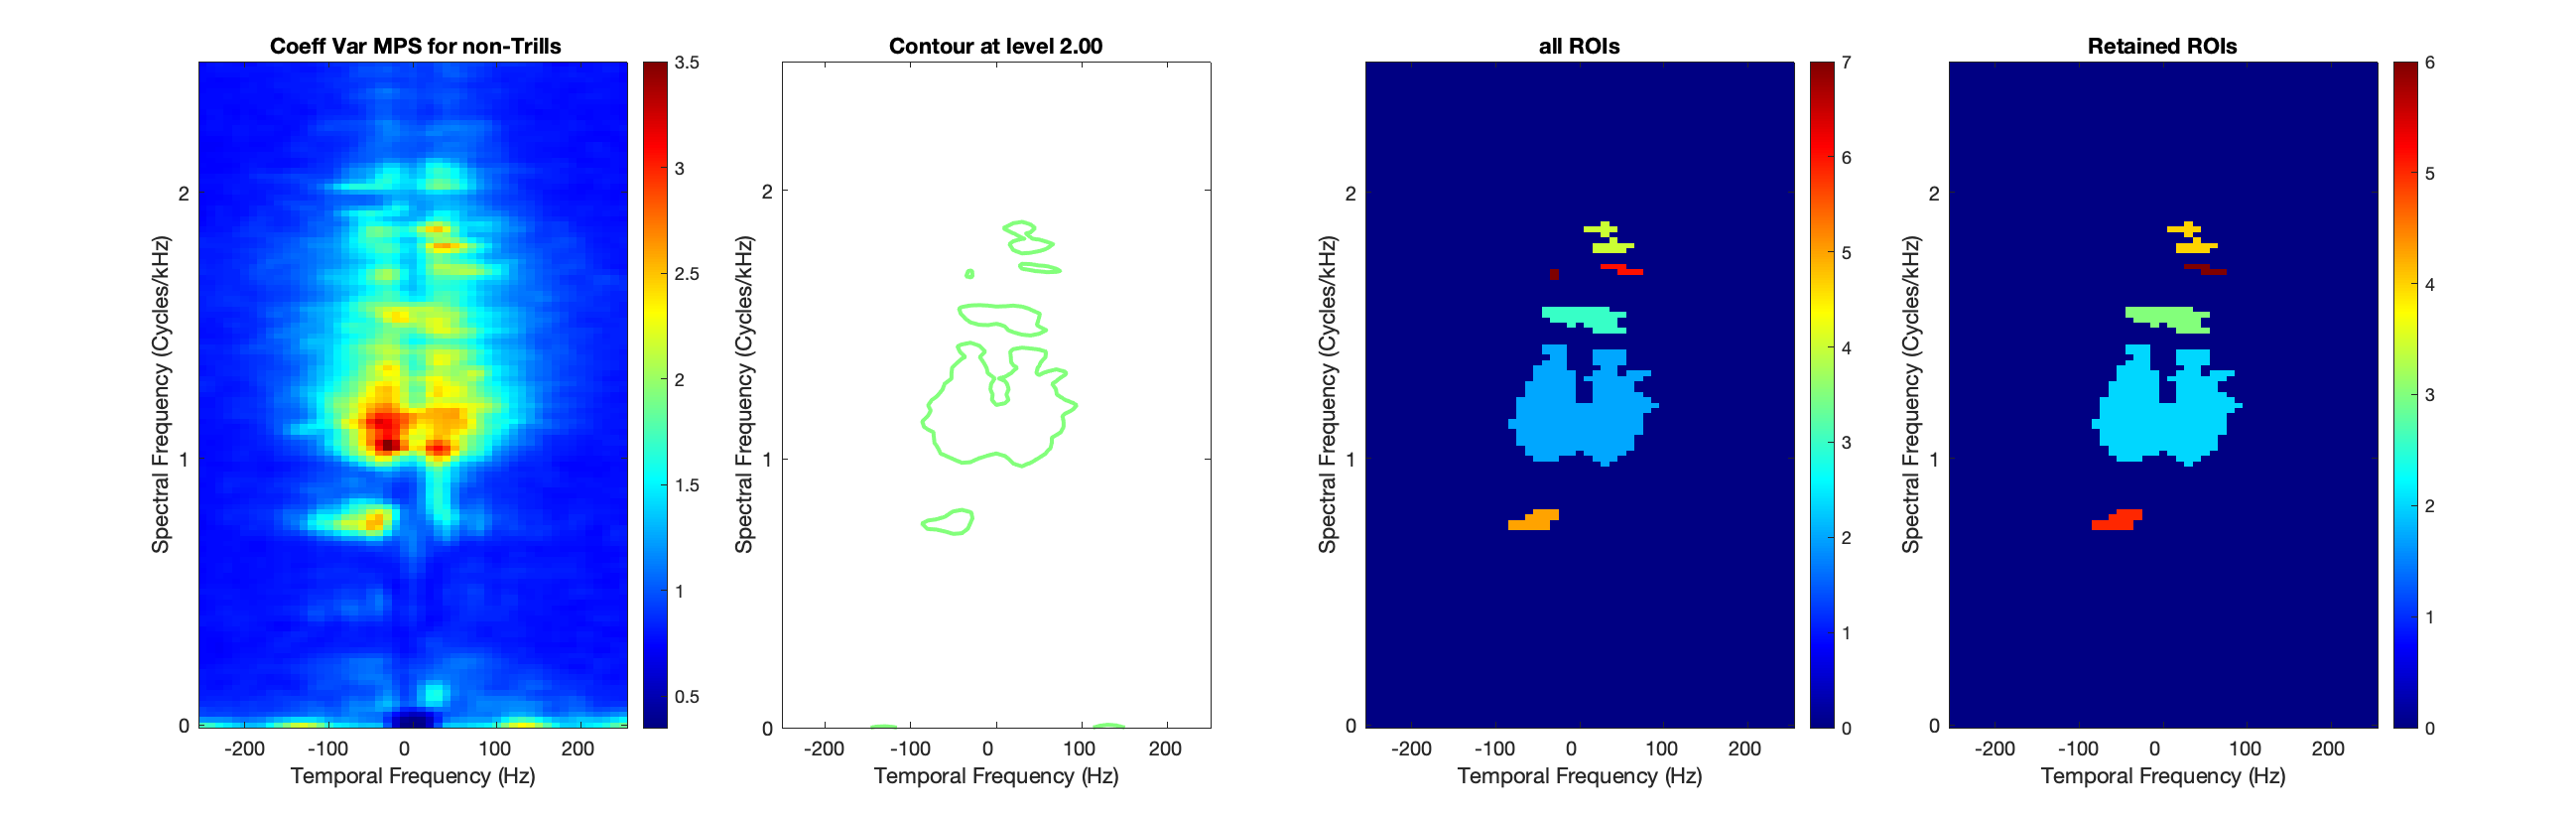


% Identify ROI in the Coeff Var MPS
Level_NonTrills =2;
F=figure(5);
set(F,'Visible','on')
clf(F)
tiledlayout(1,4)
nexttile
[CVMPS4Contour_NonTrills, Wt_4plot, Wf_4plot] = plot_mps(VarMPS, NonTrills_wf, NonTrills_wt, DBNOISE,0, [0 2.5], [-250 250],0.75);
title(' Coeff Var MPS for non-Trills')

nexttile
[Contour, Cplot] = contour(CVMPS4Contour_NonTrills,[Level_NonTrills Level_NonTrills]);
Cplot.LineWidth = 2;
% get nice X and y tick labels
MaxWf = max(floor(Wf_4plot*10^3));
YTickLabel=0:MaxWf;
YTick = nan(length(YTickLabel),1);
for yy=1:length(YTick)
    YTick(yy) = find(floor(Wf_4plot*10^3)==YTickLabel(yy),1);
end
set(gca, 'YTickLabel', YTickLabel, 'YTick', YTick)
MaxWt = max(floor(Wt_4plot*10^-2))*10^2;
XTickLabel = -MaxWt:100:MaxWt;
XTick = nan(length(XTickLabel),1);
for xx=1:length(XTick)
    [~,XTick(xx)] = min(abs(round(Wt_4plot)-XTickLabel(xx)));
end
set(gca, 'XTickLabel',XTickLabel, 'XTick', XTick)
ylabel('Spectral Frequency (Cycles/kHz)')
xlabel('Temporal Frequency (Hz)')
title(sprintf('Contour at level %.2f', Level_NonTrills))

% Identify the different contours
IndContour = find(Contour(1,:)==Level_NonTrills);
NpointsContour = Contour(2,IndContour);
[~,Ord] = sort(NpointsContour, 'descend');
NonTrills_ROI = cell(length(Ord),1);
ROI_map = zeros(size(CVMPS4Contour_NonTrills));

for cont = 1:length(IndContour)
    Cont_local = Contour(:,IndContour(Ord(cont))+(1:NpointsContour(Ord(cont))));
    NonTrills_ROI{cont} = poly2mask(Cont_local(1,:), Cont_local(2,:), size(CVMPS4Contour_NonTrills,1), size(CVMPS4Contour_NonTrills,2));
    ROI_map(logical(NonTrills_ROI{cont})) = cont+1;
end
nexttile
Im = imagesc(ROI_map);
colorbar()
axis xy
% get nice X and y tick labels
MaxWf = max(floor(Wf_4plot*10^3));
YTickLabel=0:MaxWf;
YTick = nan(length(YTickLabel),1);
for yy=1:length(YTick)
    YTick(yy) = find(floor(Wf_4plot*10^3)==YTickLabel(yy),1);
end
set(gca, 'YTickLabel', YTickLabel, 'YTick', YTick)
MaxWt = max(floor(Wt_4plot*10^-2))*10^2;
XTickLabel = -MaxWt:100:MaxWt;
XTick = nan(length(XTickLabel),1);
for xx=1:length(XTick)
    [~,XTick(xx)] = min(abs(round(Wt_4plot)-XTickLabel(xx)));
end
set(gca, 'XTickLabel',XTickLabel, 'XTick', XTick)
ylabel('Spectral Frequency (Cycles/kHz)')
xlabel('Temporal Frequency (Hz)')
title('all ROIs')

% Only keeping the larger ones
LargeContour = NpointsContour(Ord)>8;
NonTrills_ROI = NonTrills_ROI(LargeContour);
SmallContour = find(~LargeContour);
for cont = 1:sum(~LargeContour)
    ROI_map(ROI_map==(SmallContour(cont)+1)) = 0;
end
nexttile
Im = imagesc(ROI_map);
colorbar()
axis xy
% get nice X and y tick labels
MaxWf = max(floor(Wf_4plot*10^3));
YTickLabel=0:MaxWf;
YTick = nan(length(YTickLabel),1);
for yy=1:length(YTick)
    YTick(yy) = find(floor(Wf_4plot*10^3)==YTickLabel(yy),1);
end
set(gca, 'YTickLabel', YTickLabel, 'YTick', YTick)
MaxWt = max(floor(Wt_4plot*10^-2))*10^2;
XTickLabel = -MaxWt:100:MaxWt;
XTick = nan(length(XTickLabel),1);
for xx=1:length(XTick)
    [~,XTick(xx)] = min(abs(round(Wt_4plot)-XTickLabel(xx)));
end
set(gca, 'XTickLabel',XTickLabel, 'XTick', XTick)
ylabel('Spectral Frequency (Cycles/kHz)')
xlabel('Temporal Frequency (Hz)')
title('Retained ROIs')

Wf_ROI_NonTrills = Wf_4plot;
Wt_ROI_NonTrills = Wt_4plot;

save(fullfile(Path2AllData,'explore_populationSU_data.mat'), 'NonTrills_mps_mat','NonTrills_wf','NonTrills_ROI','Wf_ROI_NonTrills','Wt_ROI_NonTrills','CVMPS4Contour_NonTrills','Level_NonTrills', '-append')

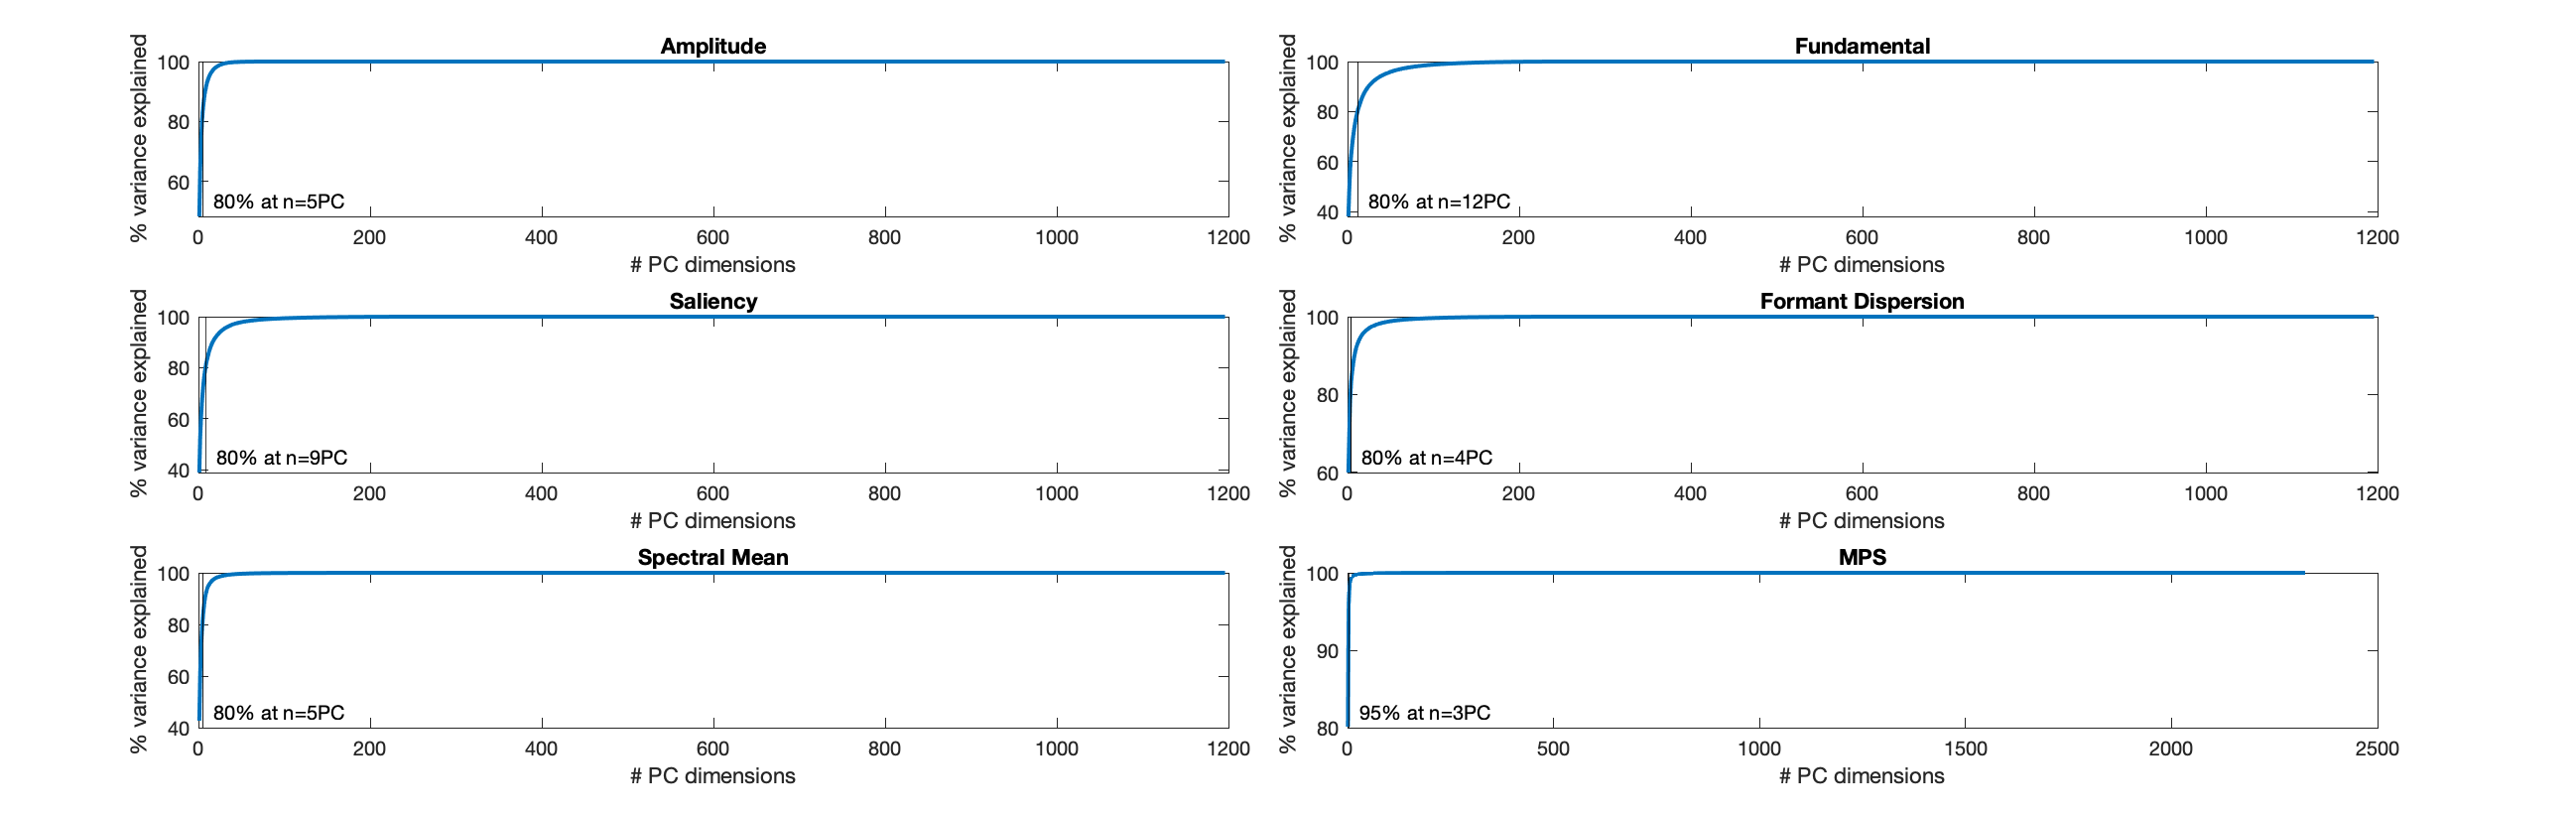

% Plot the variance explained
PercVar = 80;
t = tiledlayout(3,2,'TileSpacing','Compact');
nexttile
plot(cumsum(VarExpl_amp_NT), 'LineWidth',2)
xlabel('# PC dimensions')
ylabel('% variance explained')
hold on
vline(find(cumsum(VarExpl_amp_NT)>PercVar,1), '-k',sprintf('%d%% at n=%dPC', PercVar,find(cumsum(VarExpl_amp_NT)>PercVar,1)))
hold off
title('Amplitude')

nexttile
plot(cumsum(VarExpl_fund_NT), 'LineWidth',2)
xlabel('# PC dimensions')
ylabel('% variance explained')
hold on
vline(find(cumsum(VarExpl_fund_NT)>PercVar,1), '-k',sprintf('%d%% at n=%dPC', PercVar,find(cumsum(VarExpl_fund_NT)>PercVar,1)))
hold off
title('Fundamental')

nexttile
plot(cumsum(VarExpl_sal_NT), 'LineWidth',2)
xlabel('# PC dimensions')
ylabel('% variance explained')
hold on
vline(find(cumsum(VarExpl_sal_NT)>PercVar,1), '-k',sprintf('%d%% at n=%dPC', PercVar,find(cumsum(VarExpl_sal_NT)>PercVar,1)))
hold off
title('Saliency')

nexttile
plot(cumsum(VarExpl_formDisp_NT), 'LineWidth',2)
xlabel('# PC dimensions')
ylabel('% variance explained')
hold on
vline(find(cumsum(VarExpl_formDisp_NT)>PercVar,1), '-k',sprintf('%d%% at n=%dPC',PercVar, find(cumsum(VarExpl_formDisp_NT)>PercVar,1)))
hold off
title('Formant Dispersion')

nexttile
plot(cumsum(VarExpl_specMean_NT), 'LineWidth',2)
xlabel('# PC dimensions')
ylabel('% variance explained')
hold on
vline(find(cumsum(VarExpl_specMean_NT)>PercVar,1), '-k',sprintf('%d%% at n=%dPC',PercVar, find(cumsum(VarExpl_specMean_NT)>PercVar,1)))
hold off
title('Spectral Mean')

nexttile
plot(cumsum(VarExpl_mps_NT), 'LineWidth',2)
xlabel('# PC dimensions')
ylabel('% variance explained')
hold on
vline(find(cumsum(VarExpl_mps_NT)>95,1), '-k',sprintf('%d%% at n=%dPC',95, find(cumsum(VarExpl_mps_NT)>95,1)))
hold off
title('MPS')

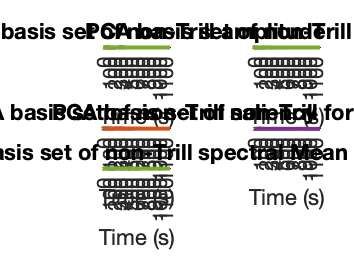

% Plot the first PC shapes
t = tiledlayout(3,2,'TileSpacing','Compact');

nexttile
NPC_amp = find(cumsum(VarExpl_amp_NT)>PercVar,1);
legend('AutoUpdate', 'On')
for ii=1:NPC_amp 
    plot(PC_amp_NT(:,ii), 'LineWidth',2,'DisplayName', sprintf('PC%d',ii));
    hold on
end
ylabel('PCA coefficients');xlabel('Time (s)');xticks(0:100:round(max(StimDuraMax_nonTrills)));xticklabels(0:100:max(StimDuraMax_nonTrills));
title('PCA basis set of non-Trill amplitude')
hold off

nexttile
NPC_fund = find(cumsum(VarExpl_fund_NT)>PercVar,1);
legend('AutoUpdate', 'On')
for ii=1:NPC_fund 
    plot(PC_fund_NT(:,ii), 'LineWidth',2, 'DisplayName', sprintf('PC%d',ii));
    hold on   
end
ylabel('PCA coefficients');xlabel('Time (s)');xticks(0:100:round(max(StimDuraMax_nonTrills)));xticklabels(0:100:max(StimDuraMax_nonTrills));
title('PCA basis set of non-Trill fundamental')
hold off

nexttile
NPC_sal = find(cumsum(VarExpl_sal_NT)>PercVar,1);
legend('AutoUpdate', 'On')
for ii=1:NPC_sal 
    plot(PC_sal_NT(:,ii), 'LineWidth',2, 'DisplayName', sprintf('PC%d',ii));
    hold on   
end
ylabel('PCA coefficients');xlabel('Time (s)');xticks(0:100:round(max(StimDuraMax_nonTrills)));xticklabels(0:100:max(StimDuraMax_nonTrills));
title('PCA basis set of non-Trill saliency')
hold off

nexttile
NPC_formDisp = find(cumsum(VarExpl_formDisp_NT)>PercVar,1);
legend('AutoUpdate', 'On')
for ii=1:NPC_formDisp 
    plot(PC_formDisp_NT(:,ii), 'LineWidth',2, 'DisplayName', sprintf('PC%d',ii));
    hold on   
end
ylabel('PCA coefficients');xlabel('Time (s)');xticks(0:100:round(max(StimDuraMax_nonTrills)));xticklabels(0:100:max(StimDuraMax_nonTrills));
title('PCA basis set of non-Trill formant dispersion')
hold off

nexttile
NPC_specMean = find(cumsum(VarExpl_specMean_NT)>PercVar,1);
legend('AutoUpdate', 'On')
for ii=1:NPC_specMean 
    plot(PC_specMean_NT(:,ii), 'LineWidth',2, 'DisplayName', sprintf('PC%d',ii));
    hold on   
end
ylabel('PCA coefficients');xlabel('Time (s)');xticks(0:100:round(max(StimDuraMax_nonTrills)));xticklabels(0:100:max(StimDuraMax_nonTrills));
title('PCA basis set of non-Trill spectral Mean')
hold off

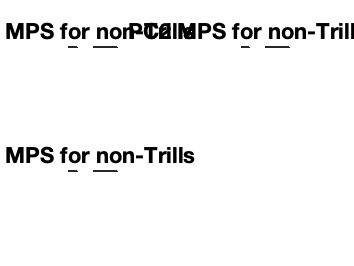


figure
tiledlayout(2,2)
nexttile
MPS_PC1 = reshape(PC_mps_NT(:,1),length(NonTrills_wf), length(NonTrills_wt));
plot_mps(MPS_PC1, NonTrills_wf, NonTrills_wt, 50,0);
title(' PC1 MPS for non-Trills')

nexttile
MPS_PC2 = reshape(PC_mps_NT(:,2),length(NonTrills_wf), length(NonTrills_wt));
plot_mps(MPS_PC1, NonTrills_wf, NonTrills_wt,50,0);
title(' PC2 MPS for non-Trills')

nexttile
MPS_PC3 = reshape(PC_mps_NT(:,3),length(NonTrills_wf), length(NonTrills_wt));
plot_mps(MPS_PC3, NonTrills_wf, NonTrills_wt,50,0);
title(' PC3 MPS for non-Trills')

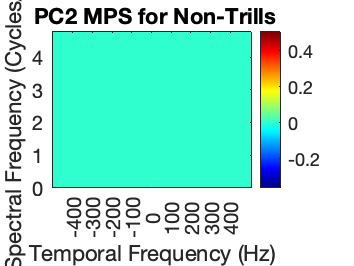

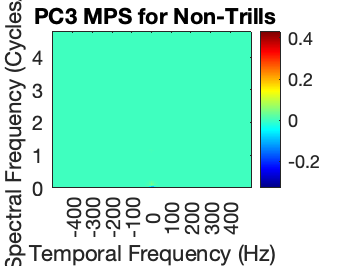

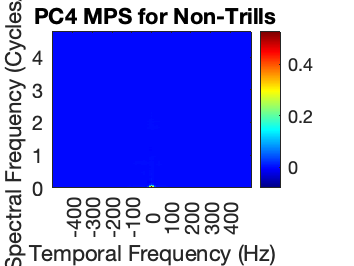

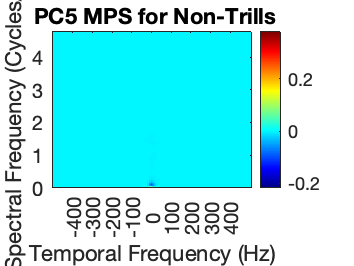

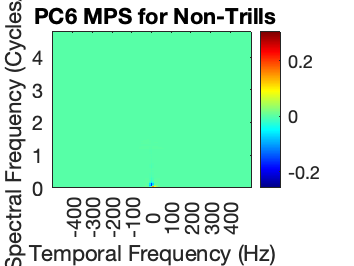

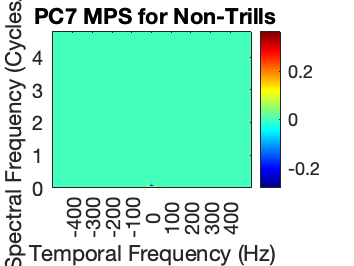

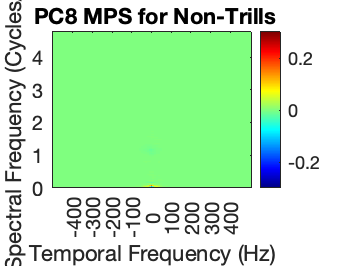

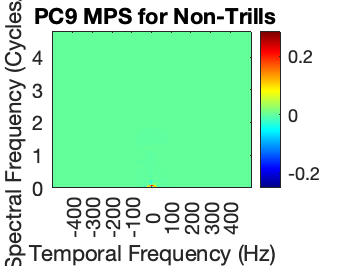

for pp = 1:20
    figure()
    MPS_PCpp = reshape(PC_mps_NT(:,pp),length(NonTrills_wf), length(NonTrills_wt));
    plot_mps(MPS_PCpp, NonTrills_wf, NonTrills_wt,50,0);
    title(sprintf(' PC%d MPS for Non-Trills', pp))
end

% plot all vocalizations in the first PC dimension of each acoustic feature
t = tiledlayout(2,2,'TileSpacing','Compact');
nexttile
scatter(Score_amp_NT(:,1),Score_fund_NT(:,1))
xlabel('PC1 amplitude')
ylabel('PC1 fundamental')

nexttile
scatter(Score_amp_NT(:,1),Score_sal_NT(:,1))
xlabel('PC1 amplitude')
ylabel('PC1 saliency')

nexttile
scatter(Score_amp_NT(:,1),Score_formDisp_NT(:,1))
xlabel('PC1 amplitude')
ylabel('PC1 formant dispersion')

nexttile
scatter(Score_amp_NT(:,1),Score_specMean_NT(:,1))
xlabel('PC1 amplitude')
ylabel('PC1 spectral mean')


% we can observe that formant dispersion has some outsider that might drive
% the pca weirdly...

t = tiledlayout(1,1);
% Obtain the matrix of acoustic distance for each cell
% retrieve for each cell the instance that was used as a reference for neural distances
AcousticVectorDistance_NT = cell(NC,1);
AcousticMatrixDistance_NT = cell(NC,1);
AcousticMatrixDistance_amp_NT = cell(NC,1);
AcousticMatrixDistance_fund_NT = cell(NC,1);
AcousticMatrixDistance_sal_NT = cell(NC,1);
AcousticMatrixDistance_specMean_NT = cell(NC,1);
AcousticMatrixDistance_formDisp_NT = cell(NC,1);
for cc=1:NC
    % Find the rows in Score that correspond to that cell
    if cc~=1
        Row1 = cumsum(NStims_nonTrills(1:cc-1));
    elseif cc==1
        Row1=0;
    end
    Score_local = [Score_amp_NT(Row1(end)+(1:NStims_nonTrills(cc)),1:NPC_amp) Score_fund_NT(Row1(end)+(1:NStims_nonTrills(cc)),1:NPC_fund) Score_sal_NT(Row1(end)+(1:NStims_nonTrills(cc)),1:NPC_sal) Score_formDisp_NT(Row1(end)+(1:NStims_nonTrills(cc)),1:NPC_formDisp) Score_specMean_NT(Row1(end)+(1:NStims_nonTrills(cc)),1:NPC_specMean)];
    % Calculate euclidean distance between pairs of vocalizations
    D = squareform(pdist(Score_local, 'seuclidean'));
    % Find the observation that we used as a reference to calculate neural
    % distances
    CentralInstance = find(NeuralVectorDistance_NT{cc} == 0);
    % Calculate the euclidean distance of all other points to the
    % reference point
    AcousticVectorDistance_NT{cc} = D(CentralInstance(1), :);
    AcousticMatrixDistance_NT{cc} = D;
    AcousticMatrixDistance_amp_NT{cc} = squareform(pdist(Score_amp_NT(Row1(end)+(1:NStims_nonTrills(cc)),1:NPC_amp), 'seuclidean'));
    AcousticMatrixDistance_fund_NT{cc} = squareform(pdist(Score_fund_NT(Row1(end)+(1:NStims_nonTrills(cc)),1:NPC_fund), 'seuclidean'));
    AcousticMatrixDistance_sal_NT{cc} = squareform(pdist(Score_sal_NT(Row1(end)+(1:NStims_nonTrills(cc)),1:NPC_sal), 'seuclidean'));
    AcousticMatrixDistance_specMean_NT{cc} = squareform(pdist(Score_specMean_NT(Row1(end)+(1:NStims_nonTrills(cc)),1:NPC_specMean), 'seuclidean'));
    AcousticMatrixDistance_formDisp_NT{cc} = squareform(pdist(Score_formDisp_NT(Row1(end)+(1:NStims_nonTrills(cc)),1:NPC_formDisp), 'seuclidean'));;
    Col = zeros(NStims_nonTrills(cc),3);
    Col(CentralInstance(1),:) = [1 0 0];
    scatter(Score_local(:,1),Score_local(:,NPC_amp + NPC_fund+1),40,Col, 'filled')
    xlabel('PC1 amp')
    ylabel('PC1 sal')
    title(sprintf('Projection of vocalizations from Cell %d/%d in PC space', cc, NC))
end

save(fullfile(Path2AllData,'explore_populationSU_data.mat'), 'AcousticMatrixDistance_NT', '-append')

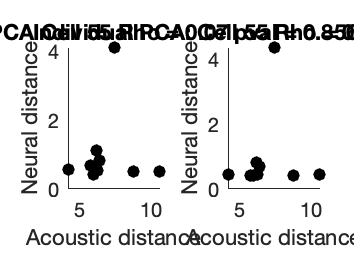

% Now for each cell, see if there is any correlation between the distance
% of vocalization in the neural space and the distance of vocalization in
% the acoustic space
figure
Rho_NT = nan(NC,2);
Rho_per_cell_NT = nan(NC,2);
for cc=1:NC
    CentralInstance = find(NeuralVectorDistance_NT{cc} == 0);
    AVD = AcousticVectorDistance_NT{cc};
    AVD(CentralInstance) = [];
    NVD1 = NeuralVectorDistance_NT{cc,1};
    NVD1(CentralInstance) = [];
    NVD2 = NeuralVectorDistance_NT{cc,2};
    NVD2(CentralInstance) = [];

    tiledlayout(1,2)
    nexttile
    scatter(AVD,NVD1, 40, 'k', 'filled')
    xlabel('Acoustic distance')
    ylabel('Neural distance')
    [Rho_NT(cc,1), Rho_NT(cc,2)] = corr(AVD',NVD1');
    title(sprintf('Population PCA Cell %d Rho = %.2f pval = %.3f',cc, Rho_NT(cc,1), Rho_NT(cc,2)))
    nexttile
    scatter(AVD,NVD2, 40, 'k', 'filled')
    xlabel('Acoustic distance')
    ylabel('Neural distance')
    [Rho_per_cell_NT(cc,1), Rho_per_cell_NT(cc,2)] = corr(AVD',NVD2');
    title(sprintf('Individual PCA: Cell %d Rho = %.2f pval = %.3f',cc, Rho_per_cell_NT(cc,1), Rho_per_cell_NT(cc,2)))
    pause()
    
end

fprintf(1, 'There are %d/%d cells for which Acoustic and Neural distances (one row of the matrix excluding the reference vocalization) are significantly correlated at 0.05', sum(Rho_NT(:,2)<0.05), NC)

There are 3/55 cells for which Acoustic and Neural distances (one row of the matrix excluding the reference vocalization) are significantly correlated at 0.05

% Run a Mantel test between matrices of Distance to find cells with
% significantly similar neural and acoustic matrices
Mantel_NT = nan(NC,4);
Mantel_per_cell_NT = nan(NC,4);
for cc=1:NC
    [Mantel_NT(cc,1), Mantel_NT(cc,2), Mantel_NT(cc,3), r] = mantelapprox(NeuralMatrixDistance_NT{cc,1}, AcousticMatrixDistance_NT{cc});
    Mantel_NT(cc,4) = r(1,2);
    [Mantel_per_cell_NT(cc,1), Mantel_per_cell_NT(cc,2), Mantel_per_cell_NT(cc,3), r] = mantelapprox(NeuralMatrixDistance_NT{cc,2}, AcousticMatrixDistance_NT{cc});
    Mantel_per_cell_NT(cc,4) = r(1,2);
end
fprintf(1, 'There are %d/%d cells for which the Mantel test on all pairs of Acoustic and Neural distances is significant at 0.05 (Cell population PCA)', sum(Mantel_NT(:,2)<0.05), NC)

There are 10/55 cells for which the Mantel test on all pairs of Acoustic and Neural distances is significant at 0.05 (Cell population PCA)

ListCells{IndUnitsNonTrills_analysis(Mantel_NT(:,2)<0.05)}

ans = '/Volumes/JulieE8T/LMCResults/59834_20190610_SSS_1-130.mat'

ans = '/Volumes/JulieE8T/LMCResults/59834_20190611_SSS_1-97.mat'

ans = '/Volumes/JulieE8T/LMCResults/59834_20190614_SSS_1-100.mat'

ans = '/Volumes/JulieE8T/LMCResults/59834_20190619_SSM_1-235.mat'

ans = '/Volumes/JulieE8T/LMCResults/59834_20190620_SSM_1-77.mat'

ans = '/Volumes/JulieE8T/LMCResults/59834_20190626_SSM_1-233.mat'

ans = '/Volumes/JulieE8T/LMCResults/59834_20190705_SSM_1-266.mat'

ans = '/Volumes/JulieE8T/LMCResults/59834_20190705_SSM_2-267.mat'

ans = '/Volumes/JulieE8T/LMCResults/59834_20190706_SSM_1-303.mat'

ans = '/Volumes/JulieE8T/LMCResults/59834_20190706_SSM_2-194.mat'

fprintf(1, 'There are %d/%d cells for which the Mantel test on all pairs of Acoustic and Neural distances is significant at 0.05 (Individual Cell PCA)', sum(Mantel_per_cell_NT(:,2)<0.05), NC)

There are 11/55 cells for which the Mantel test on all pairs of Acoustic and Neural distances is significant at 0.05 (Individual Cell PCA)

ListCells{IndUnitsNonTrills_analysis(Mantel_per_cell_NT(:,2)<0.05)}

ans = '/Volumes/JulieE8T/LMCResults/59834_20190607_SSM_1-153.mat'

ans = '/Volumes/JulieE8T/LMCResults/59834_20190610_SSS_1-130.mat'

ans = '/Volumes/JulieE8T/LMCResults/59834_20190611_SSS_1-97.mat'

ans = '/Volumes/JulieE8T/LMCResults/59834_20190620_SSM_1-77.mat'

ans = '/Volumes/JulieE8T/LMCResults/59834_20190623_SSM_1-108.mat'

ans = '/Volumes/JulieE8T/LMCResults/59834_20190626_SSM_1-233.mat'

ans = '/Volumes/JulieE8T/LMCResults/59834_20190628_SSM_1-108.mat'

ans = '/Volumes/JulieE8T/LMCResults/59834_20190702_SSM_2-101.mat'

ans = '/Volumes/JulieE8T/LMCResults/59834_20190705_SSM_1-266.mat'

ans = '/Volumes/JulieE8T/LMCResults/59834_20190705_SSM_2-267.mat'

ans = '/Volumes/JulieE8T/LMCResults/59834_20190707_SSM_1-263.mat'

% Plot the Rho values and the Mantel statistic for all cells
tiledlayout(1,2)
nexttile
Col = [Mantel_NT(:,2)<0.05 Rho_NT(:,2)<0.05 zeros(NC,1)];
scatter(Mantel_NT(:,4),Rho_NT(:,1),40, Col,"filled"); xlabel('Mantel Statistic'); ylabel('Pearson R on one row of distamce matrix')
title('Cell population PCA')
nexttile
Col = [Mantel_per_cell_NT(:,2)<0.05 Rho_per_cell_NT(:,2)<0.05 zeros(NC,1)];
scatter(Mantel_per_cell_NT(:,4),Rho_per_cell_NT(:,1),40, Col,"filled"); xlabel('Mantel Statistic'); ylabel('Pearson R on one row of distamce matrix')
title('Individual Cell PCA')

% Run Mantel tests on Distance matrices obtained only with some of the
% acoustic features
Mantel_amp_NT = nan(NC,4);
Mantel_fund_NT = nan(NC,4);
Mantel_specMean_NT = nan(NC,4);
Mantel_sal_NT = nan(NC,4);
Mantel_formDisp_NT = nan(NC,4);
Mantel_amp_per_cell_NT = nan(NC,4);
Mantel_fund_per_cell_NT = nan(NC,4);
Mantel_specMean_per_cell_NT = nan(NC,4);
Mantel_sal_per_cell_NT = nan(NC,4);
Mantel_formDisp_per_cell_NT = nan(NC,4);
for cc=1:NC
    [Mantel_amp_NT(cc,1), Mantel_amp_NT(cc,2), Mantel_amp_NT(cc,3), r] = mantelapprox(NeuralMatrixDistance_NT{cc,1}, AcousticMatrixDistance_amp_NT{cc});
    Mantel_amp_NT(cc,4) = r(1,2);
    [Mantel_sal_NT(cc,1), Mantel_sal_NT(cc,2), Mantel_sal_NT(cc,3), r] = mantelapprox(NeuralMatrixDistance_NT{cc,1}, AcousticMatrixDistance_sal_NT{cc});
    Mantel_sal_NT(cc,4) = r(1,2);
    [Mantel_fund_NT(cc,1), Mantel_fund_NT(cc,2), Mantel_fund_NT(cc,3), r] = mantelapprox(NeuralMatrixDistance_NT{cc,1}, AcousticMatrixDistance_fund_NT{cc});
    Mantel_fund_NT(cc,4) = r(1,2);
    [Mantel_specMean_NT(cc,1), Mantel_specMean_NT(cc,2), Mantel_specMean_NT(cc,3), r] = mantelapprox(NeuralMatrixDistance_NT{cc,1}, AcousticMatrixDistance_specMean_NT{cc});
    Mantel_specMean_NT(cc,4) = r(1,2);
    [Mantel_formDisp_NT(cc,1), Mantel_formDisp_NT(cc,2), Mantel_formDisp_NT(cc,3), r] = mantelapprox(NeuralMatrixDistance_NT{cc,1}, AcousticMatrixDistance_formDisp_NT{cc});
    Mantel_formDisp_NT(cc,4) = r(1,2);

    [Mantel_amp_per_cell_NT(cc,1), Mantel_amp_per_cell_NT(cc,2), Mantel_amp_per_cell_NT(cc,3), r] = mantelapprox(NeuralMatrixDistance_NT{cc,2}, AcousticMatrixDistance_amp_NT{cc});
    Mantel_amp_per_cell_NT(cc,4) = r(1,2);
    [Mantel_sal_per_cell_NT(cc,1), Mantel_sal_per_cell_NT(cc,2), Mantel_sal_per_cell_NT(cc,3), r] = mantelapprox(NeuralMatrixDistance_NT{cc,2}, AcousticMatrixDistance_sal_NT{cc});
    Mantel_sal_per_cell_NT(cc,4) = r(1,2);
    [Mantel_fund_per_cell_NT(cc,1), Mantel_fund_per_cell_NT(cc,2), Mantel_fund_per_cell_NT(cc,3), r] = mantelapprox(NeuralMatrixDistance_NT{cc,2}, AcousticMatrixDistance_fund_NT{cc});
    Mantel_fund_per_cell_NT(cc,4) = r(1,2);
    [Mantel_specMean_per_cell_NT(cc,1), Mantel_specMean_per_cell_NT(cc,2), Mantel_specMean_per_cell_NT(cc,3), r] = mantelapprox(NeuralMatrixDistance_NT{cc,2}, AcousticMatrixDistance_specMean_NT{cc});
    Mantel_specMean_per_cell_NT(cc,4) = r(1,2);
    [Mantel_formDisp_per_cell_NT(cc,1), Mantel_formDisp_per_cell_NT(cc,2), Mantel_formDisp_per_cell_NT(cc,3), r] = mantelapprox(NeuralMatrixDistance_NT{cc,2}, AcousticMatrixDistance_formDisp_NT{cc});
    Mantel_formDisp_per_cell_NT(cc,4) = r(1,2);
end
fprintf(1, 'Cell Population PCA: There are %d/%d cells for which the Mantel test on all pairs of amplitude and Neural distances is significant at 0.05', sum(Mantel_amp_NT(:,2)<0.05), NC)

Cell Population PCA: There are 11/55 cells for which the Mantel test on all pairs of amplitude and Neural distances is significant at 0.05

ListCells{IndUnitsNonTrills_analysis(Mantel_amp_NT(:,2)<0.05)}

ans = '/Volumes/JulieE8T/LMCResults/59834_20190607_SSM_1-153.mat'

ans = '/Volumes/JulieE8T/LMCResults/59834_20190611_SSS_1-97.mat'

ans = '/Volumes/JulieE8T/LMCResults/59834_20190614_SSS_1-100.mat'

ans = '/Volumes/JulieE8T/LMCResults/59834_20190618_SSM_1-73.mat'

ans = '/Volumes/JulieE8T/LMCResults/59834_20190619_SSM_1-235.mat'

ans = '/Volumes/JulieE8T/LMCResults/59834_20190620_SSM_1-77.mat'

ans = '/Volumes/JulieE8T/LMCResults/59834_20190626_SSM_1-233.mat'

ans = '/Volumes/JulieE8T/LMCResults/59834_20190705_SSM_1-266.mat'

ans = '/Volumes/JulieE8T/LMCResults/59834_20190705_SSM_2-267.mat'

ans = '/Volumes/JulieE8T/LMCResults/59834_20190706_SSM_2-194.mat'

ans = '/Volumes/JulieE8T/LMCResults/59834_20190711_SSM_2-265.mat'

fprintf(1, 'Individual Cell PCA: There are %d/%d cells for which the Mantel test on all pairs of amplitude and Neural distances is significant at 0.05', sum(Mantel_amp_per_cell_NT(:,2)<0.05), NC)

Individual Cell PCA: There are 6/55 cells for which the Mantel test on all pairs of amplitude and Neural distances is significant at 0.05

ListCells{IndUnitsNonTrills_analysis(Mantel_amp_per_cell_NT(:,2)<0.05)}

ans = '/Volumes/JulieE8T/LMCResults/59834_20190607_SSM_1-153.mat'

ans = '/Volumes/JulieE8T/LMCResults/59834_20190620_SSM_1-77.mat'

ans = '/Volumes/JulieE8T/LMCResults/59834_20190626_SSM_1-233.mat'

ans = '/Volumes/JulieE8T/LMCResults/59834_20190702_SSM_2-101.mat'

ans = '/Volumes/JulieE8T/LMCResults/59834_20190705_SSM_1-266.mat'

ans = '/Volumes/JulieE8T/LMCResults/59834_20190705_SSM_2-267.mat'

fprintf(1, 'Cell Population PCA:There are %d/%d cells for which the Mantel test on all pairs of saliency and Neural distances is significant at 0.05', sum(Mantel_sal_NT(:,2)<0.05), NC)

Cell Population PCA:There are 12/55 cells for which the Mantel test on all pairs of saliency and Neural distances is significant at 0.05

ListCells{IndUnitsNonTrills_analysis(Mantel_sal_NT(:,2)<0.05)}

ans = '/Volumes/JulieE8T/LMCResults/59834_20190614_SSS_1-100.mat'

ans = '/Volumes/JulieE8T/LMCResults/59834_20190619_SSM_1-235.mat'

ans = '/Volumes/JulieE8T/LMCResults/59834_20190620_SSM_1-77.mat'

ans = '/Volumes/JulieE8T/LMCResults/59834_20190623_SSM_1-108.mat'

ans = '/Volumes/JulieE8T/LMCResults/59834_20190626_SSS_1-109.mat'

ans = '/Volumes/JulieE8T/LMCResults/59834_20190630_SSM_1-219.mat'

ans = '/Volumes/JulieE8T/LMCResults/59834_20190702_SSM_2-101.mat'

ans = '/Volumes/JulieE8T/LMCResults/59834_20190705_SSM_2-267.mat'

ans = '/Volumes/JulieE8T/LMCResults/59834_20190706_SSM_1-303.mat'

ans = '/Volumes/JulieE8T/LMCResults/59834_20190706_SSM_2-194.mat'

ans = '/Volumes/JulieE8T/LMCResults/59834_20190711_SSM_2-265.mat'

ans = '/Volumes/JulieE8T/LMCResults/11689_20190118_SSM_1-81.mat'

fprintf(1, 'Individual Cell PCA: There are %d/%d cells for which the Mantel test on all pairs of saliency and Neural distances is significant at 0.05', sum(Mantel_sal_per_cell_NT(:,2)<0.05), NC)

Individual Cell PCA: There are 12/55 cells for which the Mantel test on all pairs of saliency and Neural distances is significant at 0.05

ListCells{IndUnitsNonTrills_analysis(Mantel_sal_per_cell_NT(:,2)<0.05)}

ans = '/Volumes/JulieE8T/LMCResults/59834_20190610_SSS_1-130.mat'

ans = '/Volumes/JulieE8T/LMCResults/59834_20190620_SSM_1-77.mat'

ans = '/Volumes/JulieE8T/LMCResults/59834_20190623_SSM_1-108.mat'

ans = '/Volumes/JulieE8T/LMCResults/59834_20190626_SSS_1-109.mat'

ans = '/Volumes/JulieE8T/LMCResults/59834_20190628_SSM_1-108.mat'

ans = '/Volumes/JulieE8T/LMCResults/59834_20190629_SSM_1-119.mat'

ans = '/Volumes/JulieE8T/LMCResults/59834_20190702_SSM_2-101.mat'

ans = '/Volumes/JulieE8T/LMCResults/59834_20190705_SSM_1-266.mat'

ans = '/Volumes/JulieE8T/LMCResults/59834_20190705_SSM_2-267.mat'

ans = '/Volumes/JulieE8T/LMCResults/59834_20190707_SSM_1-263.mat'

ans = '/Volumes/JulieE8T/LMCResults/59834_20190711_SSM_1-98.mat'

ans = '/Volumes/JulieE8T/LMCResults/11689_20190118_SSM_1-81.mat'

fprintf(1, 'Cell Population PCA: There are %d/%d cells for which the Mantel test on all pairs of fundamental and Neural distances is significant at 0.05', sum(Mantel_fund_NT(:,2)<0.05), NC)

Cell Population PCA: There are 5/55 cells for which the Mantel test on all pairs of fundamental and Neural distances is significant at 0.05

ListCells{IndUnitsNonTrills_analysis(Mantel_fund_NT(:,2)<0.05)}

ans = '/Volumes/JulieE8T/LMCResults/59834_20190611_SSS_1-97.mat'

ans = '/Volumes/JulieE8T/LMCResults/59834_20190620_SSM_1-77.mat'

ans = '/Volumes/JulieE8T/LMCResults/59834_20190626_SSM_1-233.mat'

ans = '/Volumes/JulieE8T/LMCResults/59834_20190705_SSM_1-266.mat'

ans = '/Volumes/JulieE8T/LMCResults/59834_20190705_SSM_2-267.mat'

fprintf(1, 'Individual Cell PCA: There are %d/%d cells for which the Mantel test on all pairs of fundamental and Neural distances is significant at 0.05', sum(Mantel_fund_per_cell_NT(:,2)<0.05), NC)

Individual Cell PCA: There are 7/55 cells for which the Mantel test on all pairs of fundamental and Neural distances is significant at 0.05

ListCells{IndUnitsNonTrills_analysis(Mantel_fund_per_cell_NT(:,2)<0.05)}

ans = '/Volumes/JulieE8T/LMCResults/59834_20190611_SSS_1-97.mat'

ans = '/Volumes/JulieE8T/LMCResults/59834_20190620_SSM_1-77.mat'

ans = '/Volumes/JulieE8T/LMCResults/59834_20190626_SSM_1-233.mat'

ans = '/Volumes/JulieE8T/LMCResults/59834_20190629_SSM_1-105.mat'

ans = '/Volumes/JulieE8T/LMCResults/59834_20190702_SSM_2-101.mat'

ans = '/Volumes/JulieE8T/LMCResults/59834_20190705_SSM_1-266.mat'

ans = '/Volumes/JulieE8T/LMCResults/59834_20190705_SSM_2-267.mat'

fprintf(1, 'Cell population PCA: There are %d/%d cells for which the Mantel test on all pairs of spectral mean and Neural distances is significant at 0.05', sum(Mantel_specMean_NT(:,2)<0.05), NC)

Cell population PCA: There are 11/55 cells for which the Mantel test on all pairs of spectral mean and Neural distances is significant at 0.05

ListCells{IndUnitsNonTrills_analysis(Mantel_specMean_NT(:,2)<0.05)}

ans = '/Volumes/JulieE8T/LMCResults/59834_20190611_SSS_1-97.mat'

ans = '/Volumes/JulieE8T/LMCResults/59834_20190614_SSS_1-100.mat'

ans = '/Volumes/JulieE8T/LMCResults/59834_20190619_SSM_1-235.mat'

ans = '/Volumes/JulieE8T/LMCResults/59834_20190620_SSM_1-77.mat'

ans = '/Volumes/JulieE8T/LMCResults/59834_20190623_SSM_1-108.mat'

ans = '/Volumes/JulieE8T/LMCResults/59834_20190626_SSS_1-109.mat'

ans = '/Volumes/JulieE8T/LMCResults/59834_20190702_SSM_2-101.mat'

ans = '/Volumes/JulieE8T/LMCResults/59834_20190705_SSM_2-267.mat'

ans = '/Volumes/JulieE8T/LMCResults/59834_20190706_SSM_2-194.mat'

ans = '/Volumes/JulieE8T/LMCResults/59834_20190707_SSM_1-263.mat'

ans = '/Volumes/JulieE8T/LMCResults/59834_20190711_SSM_2-265.mat'

fprintf(1, 'Individal cell PCA: There are %d/%d cells for which the Mantel test on all pairs of spectral mean and Neural distances is significant at 0.05', sum(Mantel_specMean_per_cell_NT(:,2)<0.05), NC)

Individal cell PCA: There are 10/55 cells for which the Mantel test on all pairs of spectral mean and Neural distances is significant at 0.05

ListCells{IndUnitsNonTrills_analysis(Mantel_specMean_per_cell_NT(:,2)<0.05)}

ans = '/Volumes/JulieE8T/LMCResults/59834_20190619_SSM_1-235.mat'

ans = '/Volumes/JulieE8T/LMCResults/59834_20190623_SSM_1-108.mat'

ans = '/Volumes/JulieE8T/LMCResults/59834_20190628_SSM_1-108.mat'

ans = '/Volumes/JulieE8T/LMCResults/59834_20190629_SSM_1-119.mat'

ans = '/Volumes/JulieE8T/LMCResults/59834_20190702_SSM_2-101.mat'

ans = '/Volumes/JulieE8T/LMCResults/59834_20190705_SSM_1-266.mat'

ans = '/Volumes/JulieE8T/LMCResults/59834_20190705_SSM_2-267.mat'

ans = '/Volumes/JulieE8T/LMCResults/59834_20190706_SSM_1-303.mat'

ans = '/Volumes/JulieE8T/LMCResults/59834_20190707_SSM_1-263.mat'

ans = '/Volumes/JulieE8T/LMCResults/59834_20190711_SSM_2-265.mat'

fprintf(1, 'Cell population PCA: There are %d/%d cells for which the Mantel test on all pairs of formant dispersion and Neural distances is significant at 0.05', sum(Mantel_formDisp_NT(:,2)<0.05), NC)

Cell population PCA: There are 7/55 cells for which the Mantel test on all pairs of formant dispersion and Neural distances is significant at 0.05

ListCells{IndUnitsNonTrills_analysis(Mantel_formDisp_NT(:,2)<0.05)}

ans = '/Volumes/JulieE8T/LMCResults/59834_20190614_SSS_1-100.mat'

ans = '/Volumes/JulieE8T/LMCResults/59834_20190620_SSM_1-77.mat'

ans = '/Volumes/JulieE8T/LMCResults/59834_20190623_SSM_1-108.mat'

ans = '/Volumes/JulieE8T/LMCResults/59834_20190626_SSS_1-109.mat'

ans = '/Volumes/JulieE8T/LMCResults/59834_20190705_SSM_2-267.mat'

ans = '/Volumes/JulieE8T/LMCResults/59834_20190706_SSM_1-303.mat'

ans = '/Volumes/JulieE8T/LMCResults/59834_20190711_SSM_2-265.mat'

fprintf(1, 'Individual Cell PCA: There are %d/%d cells for which the Mantel test on all pairs of formant dispersion and Neural distances is significant at 0.05', sum(Mantel_formDisp_per_cell_NT(:,2)<0.05), NC)

Individual Cell PCA: There are 10/55 cells for which the Mantel test on all pairs of formant dispersion and Neural distances is significant at 0.05

ListCells{IndUnitsNonTrills_analysis(Mantel_formDisp_per_cell_NT(:,2)<0.05)}

ans = '/Volumes/JulieE8T/LMCResults/59834_20190620_SSM_1-77.mat'

ans = '/Volumes/JulieE8T/LMCResults/59834_20190623_SSM_1-108.mat'

ans = '/Volumes/JulieE8T/LMCResults/59834_20190626_SSS_1-109.mat'

ans = '/Volumes/JulieE8T/LMCResults/59834_20190627_SSS_4-316.mat'

ans = '/Volumes/JulieE8T/LMCResults/59834_20190628_SSM_1-108.mat'

ans = '/Volumes/JulieE8T/LMCResults/59834_20190629_SSM_1-105.mat'

ans = '/Volumes/JulieE8T/LMCResults/59834_20190705_SSM_2-267.mat'

ans = '/Volumes/JulieE8T/LMCResults/59834_20190707_SSM_1-263.mat'

ans = '/Volumes/JulieE8T/LMCResults/59834_20190711_SSM_1-98.mat'

ans = '/Volumes/JulieE8T/LMCResults/59834_20190711_SSM_2-265.mat'

% Plot the Mantel statistics for all cells
t = tiledlayout(3,2,'TileSpacing','Compact');
nexttile
Col = [Mantel_NT(:,2)<0.05 Mantel_amp_NT(:,2)<0.05 zeros(NC,1)];
scatter(Mantel_NT(:,1),Mantel_amp_NT(:,1),40, Col,"filled"); xlabel('Mantel All'); ylabel('Mantel Amplitude')
title('Amplitude')

nexttile
Col = [Mantel_NT(:,2)<0.05 Mantel_fund_NT(:,2)<0.05 zeros(NC,1)];
scatter(Mantel_NT(:,1),Mantel_fund_NT(:,1),40, Col,"filled"); xlabel('Mantel All'); ylabel('Mantel Fundamental')
title('Fundamental')

nexttile
Col = [Mantel_NT(:,2)<0.05 Mantel_sal_NT(:,2)<0.05 zeros(NC,1)];
scatter(Mantel_NT(:,1),Mantel_sal_NT(:,1),40, Col,"filled"); xlabel('Mantel All'); ylabel('Mantel Saliency')
title('Saliency')

nexttile
Col = [Mantel_NT(:,2)<0.05 Mantel_specMean_NT(:,2)<0.05 zeros(NC,1)];
scatter(Mantel_NT(:,1),Mantel_specMean_NT(:,1),40, Col,"filled"); xlabel('Mantel All'); ylabel('Mantel spectral mean')
title('Spectral mean')

nexttile
Col = [Mantel_NT(:,2)<0.05 Mantel_formDisp_NT(:,2)<0.05 zeros(NC,1)];
scatter(Mantel_NT(:,1),Mantel_formDisp_NT(:,1),40, Col,"filled"); xlabel('Mantel All'); ylabel('Mantel formant Dispersion')
title('Formants dispersion')

% Look in more details the significant cells neural responses
% amplitude cells
% plot the matrices of acoustic and neural distances side by side
fprintf(1,'Matrices of distance for significant amplitude cells')
Amp_cells = find(Mantel_amp_NT(:,2)<0.05);
t = tiledlayout(length(Amp_cells),2);
for cc=1:length(Amp_cells)
    ListCells{IndUnitsNonTrills_analysis(Amp_cells(cc))}
    nexttile
    imagesc(AcousticMatrixDistance_amp_NT{Amp_cells(cc)})
    colorbar()
    title('Amplitude')
    nexttile
    imagesc(NeuralMatrixDistance_NT{Amp_cells(cc)})
    colorbar()
    title('Neural')

end

pThresh = 0.01;
% For each cell find the extreme quartile neural responses in PC space and
% plot the time varying acoustic feature of  the  corresponding
% voclaizations
Amp_cells = unique([find(Mantel_amp_NT(:,2)<pThresh); find(Mantel_amp_per_cell_NT(:,2)<pThresh)]);
for cc=1:length(Amp_cells)
    % Find the rows in PCA Score, spike rate and amplitude that correspond to that cell
    if Amp_cells(cc)~=1
        Row1 = cumsum(NStims_nonTrills(1:Amp_cells(cc)-1));
    elseif Amp_cells(cc)==1
        Row1=0;
    end
    Score_local = Score_NonTrill(Row1(end)+(1:NStims_nonTrills(Amp_cells(cc))),1:NPC_NT);
    RateNonTrills_mat_local = RateNonTrills_mat(Row1(end)+(1:NStims_nonTrills(Amp_cells(cc))),:);
    Trills_amp_mat_local = NonTrills_amp_mat(Row1(end)+(1:NStims_nonTrills(Amp_cells(cc))),:);
    Score_local2 = Score_per_cell_NT{Amp_cells(cc)}(:,1:NPC_per_cell_NT(Amp_cells(cc)));

    plot_extreme_clusters(Score_local,RateNonTrills_mat_local, Trills_amp_mat_local,  NeuralMatrixDistance_NT{Amp_cells(cc),1}, AcousticMatrixDistance_amp_NT{Amp_cells(cc)}, Amplitude, 'Amplitude')
    suplabel(sprintf('Pop PCA %s r = %.3f  p = %.4f', ListCells{IndUnitsNonTrills_analysis(Amp_cells(cc))},Mantel_amp_NT(Amp_cells(cc),4),Mantel_amp_NT(Amp_cells(cc),2)), 't');
    plot_extreme_clusters(Score_local2,RateNonTrills_mat_local, Trills_amp_mat_local,  NeuralMatrixDistance_NT{Amp_cells(cc),2}, AcousticMatrixDistance_amp_NT{Amp_cells(cc)}, Amplitude, 'Amplitude')
    suplabel(sprintf('Cell PCA %s r = %.3f  p = %.4f', ListCells{IndUnitsNonTrills_analysis(Amp_cells(cc))},Mantel_amp_per_cell_NT(Amp_cells(cc),4),Mantel_amp_per_cell_NT(Amp_cells(cc),2)), 't');
end

% For each cell find the extreme quartile neural responses in PC space and
% plot the time varying acoustic feature of  the  corresponding
% voclaizations
Sal_cells = unique([find(Mantel_sal_NT(:,2)<pThresh); find(Mantel_sal_per_cell_NT(:,2)<pThresh)]);
for cc=1:length(Sal_cells)
    % Find the rows in PCA Score, spike rate and amplitude that correspond to that cell
    if Sal_cells(cc)~=1
        Row1 = cumsum(NStims_nonTrills(1:Sal_cells(cc)-1));
    elseif Sal_cells(cc)==1
        Row1=0;
    end
    Score_local = Score_NonTrill(Row1(end)+(1:NStims_nonTrills(Sal_cells(cc))),1:NPC_NT);
    RateNonTrills_mat_local = RateNonTrills_mat(Row1(end)+(1:NStims_nonTrills(Sal_cells(cc))),:);
    Trills_sal_mat_local = NonTrills_sal_mat(Row1(end)+(1:NStims_nonTrills(Sal_cells(cc))),:);
    Score_local2 = Score_per_cell_NT{Sal_cells(cc)}(:,1:NPC_per_cell_NT(Sal_cells(cc)));

    plot_extreme_clusters(Score_local,RateNonTrills_mat_local, Trills_sal_mat_local,  NeuralMatrixDistance_NT{Sal_cells(cc),1}, AcousticMatrixDistance_sal_NT{Sal_cells(cc)}, Saliency, 'Saliency')
    suplabel(sprintf('Pop PCA: %s r = %.3f  p = %.4f', ListCells{IndUnitsNonTrills_analysis(Sal_cells(cc))},Mantel_sal_NT(Sal_cells(cc),4),Mantel_sal_NT(Sal_cells(cc),2)), 't');
    plot_extreme_clusters(Score_local2,RateNonTrills_mat_local, Trills_sal_mat_local,  NeuralMatrixDistance_NT{Sal_cells(cc),2}, AcousticMatrixDistance_sal_NT{Sal_cells(cc)}, Saliency, 'Saliency')
    suplabel(sprintf('Cell PCA: %s r = %.3f  p = %.4f', ListCells{IndUnitsNonTrills_analysis(Sal_cells(cc))},Mantel_sal_per_cell_NT(Sal_cells(cc),4),Mantel_sal_per_cell_NT(Sal_cells(cc),2)), 't');
end

% For each cell find the extreme quartile neural responses in PC space and
% plot the time varying acoustic feature of  the  corresponding
% voclaizations
% Fund_cells = unique([find(Mantel_fund(:,2)<0.05); find(Mantel_fund_per_cell (:,2)<0.05)]);
for cc=1:length(Fund_cells)
    % Find the rows in PCA Score, spike rate and amplitude that correspond to that cell
    if Fund_cells(cc)~=1
        Row1 = cumsum(NStims_nonTrills(1:Fund_cells(cc)-1));
    elseif Fund_cells(cc)==1
        Row1=0;
    end
    Score_local = Score_NonTrill(Row1(end)+(1:NStims_nonTrills(Fund_cells(cc))),1:NPC_NT);
    RateNonTrills_mat_local = RateNonTrills_mat(Row1(end)+(1:NStims_nonTrills(Fund_cells(cc))),:);
    Trills_fund_mat_local = NonTrills_fund_mat(Row1(end)+(1:NStims_nonTrills(Fund_cells(cc))),:);
    Score_local2 = Score_per_cell_NT{Fund_cells(cc)}(:,1:NPC_per_cell_NT(Fund_cells(cc)));

    plot_extreme_clusters(Score_local,RateNonTrills_mat_local, Trills_fund_mat_local,  NeuralMatrixDistance_NT{Fund_cells(cc),1}, AcousticMatrixDistance_fund_NT{Fund_cells(cc)}, SoundFund, 'Fundamental')
%     suplabel(sprintf('Pop PCA: %s r = %.3f  p = %.4f', ListCells{IndUnitsNonTrills_analysis(Fund_cells(cc))},Mantel_fund(Fund_cells(cc),4),Mantel_fund(Fund_cells(cc),2)), 't');
    plot_extreme_clusters(Score_local2,RateNonTrills_mat_local, Trills_fund_mat_local,  NeuralMatrixDistance_NT{Fund_cells(cc),2}, AcousticMatrixDistance_fund_NT{Fund_cells(cc)}, SoundFund, 'Fundamental')
    suplabel(sprintf('Cell PCA: %s r = %.3f  p = %.4f', ListCells{IndUnitsNonTrills_analysis(Fund_cells(cc))},Mantel_fund_per_cell_NT(Fund_cells(cc),4),Mantel_fund_per_cell_NT(Fund_cells(cc),2)), 't');
end

% For each cell find the extreme quartile neural responses in PC space and
% plot the time varying acoustic feature of  the  corresponding
% voclaizations
SpecM_cells = unique([find(Mantel_specMean_NT(:,2)<pThresh);find(Mantel_specMean_per_cell_NT(:,2)<pThresh)]);
for cc=1:length(SpecM_cells)
    % Find the rows in PCA Score, spike rate and amplitude that correspond to that cell
    if SpecM_cells(cc)~=1
        Row1 = cumsum(NStims_nonTrills(1:SpecM_cells(cc)-1));
    elseif SpecM_cells(cc)==1
        Row1=0;
    end
    Score_local = Score_NonTrill(Row1(end)+(1:NStims_nonTrills(SpecM_cells(cc))),1:NPC_NT);xpe
    RateNonTrills_mat_local = RateNonTrills_mat(Row1(end)+(1:NStims_nonTrills(SpecM_cells(cc))),:);
    Trills_specM_mat_local = NonTrills_specMean_mat(Row1(end)+(1:NStims_nonTrills(SpecM_cells(cc))),:);
    Score_local2 = Score_per_cell_NT{SpecM_cells(cc)}(:,1:NPC_per_cell_NT(SpecM_cells(cc)));

    plot_extreme_clusters(Score_local,RateNonTrills_mat_local, Trills_specM_mat_local,  NeuralMatrixDistance_NT{SpecM_cells(cc),1}, AcousticMatrixDistance_specMean_NT{SpecM_cells(cc)}, SoundSpecMean, 'SpectralMean')
    suplabel(sprintf('Pop PCA: %s r = %.3f  p = %.4f', ListCells{IndUnitsNonTrills_analysis(SpecM_cells(cc))},Mantel_specMean_NT(SpecM_cells(cc),4),Mantel_specMean_NT(SpecM_cells(cc),2)), 't');
    plot_extreme_clusters(Score_local2,RateNonTrills_mat_local, Trills_specM_mat_local,  NeuralMatrixDistance_NT{SpecM_cells(cc),2}, AcousticMatrixDistance_specMean_NT{SpecM_cells(cc)}, SoundSpecMean, 'SpectralMean')
    suplabel(sprintf('Cell PCA: %s r = %.3f  p = %.4f', ListCells{IndUnitsNonTrills_analysis(SpecM_cells(cc))},Mantel_specMean_per_cell_NT(SpecM_cells(cc),4),Mantel_specMean_per_cell_NT(SpecM_cells(cc),2)), 't');
end

## Analysis using the MPS

For each cell, find the extreme quartiles in the Neural space, then calculate the average MPS for each quartile and the distance between these average MPS, Bootstrap the calculation by calculating 10000 groups of vocalizations of the same sizes as quartile groups and finding the distribution of MPS values for all of them.

NBoot = 10000;
ClustNum = 4;
DBNoise = 50;

MPSDiff_NT = cell(NC,1);
% MPSDiff_p = cell(NC,1);
MPSDiff_NT_rand_all = cell(NC,1);
MPSDiff_NT_randRMS = cell(NC,1);
MPSDiff_NT_RMS = nan(NC,length(NonTrills_ROI));
MPSDiff_NT_RMSp = nan(NC,length(NonTrills_ROI));


MPSCoeffDiff_NT = cell(NC,1);
% MPSCoeffDiff_p = cell(NC,1);
MPSCoeffDiff_NT_rand_all = cell(NC,1);
MPSCoeffDiff_NT_randRMS = cell(NC,1);
MPSCoeffDiff_NT_RMS = nan(NC,length(NonTrills_ROI));
MPSCoeffDiff_NT_RMSp = nan(NC,length(NonTrills_ROI));

Wf_pos = logical((NonTrills_wf>=0) .* (NonTrills_wf*10^3<=2.5));
Wt_narrow = logical((NonTrills_wt>=-250) .* (NonTrills_wt<=250));

for cc=1:NC
    % find the extreme quartiles in Neural PC space + Z-scored Rate
    ZSRate = (MeanRateNonTrills{cc} - mean(MeanRateNonTrills{cc}))./std(MeanRateNonTrills{cc});
    Score_local = [ZSRate Score_per_cell_NT{cc}(:,1:min(NPC_per_cell_NT(cc), floor(NStims_nonTrills(cc)/10)))];
    [Idx, ClustMaxD] = find_extreme_clusters(Score_local, ClustNum, {'kmeans', 'RecursivePoint'});
    if isnan(Idx)
        [Idx, ClustMaxD] = find_extreme_clusters(Score_local, ClustNum, {'kmeans', 'RecursiveCluster'});
    end

    
    % Get the average MPS for both clusters
    NonTrills_mps_local = cell(length(ClustMaxD),1);
    for Clust = 1:length(ClustMaxD)
        NonTrills_mps_local{Clust} = mean([NonTrills_mps{cc}{Idx == ClustMaxD(Clust)}],2);
    end

    % Get the average MPS over all vocalizations for that cell
    NonTrills_mps_mean = mean([NonTrills_mps{cc}{:}],2);

    % Get the MPS difference between the 2 clusters
    MPSDiff_NT_vec = NonTrills_mps_local{1} - NonTrills_mps_local{2};
    MPSDiff_NT_mat = reshape(MPSDiff_NT_vec, length(NonTrills_wf), length(NonTrills_wt));
    MPSDiff_NT{cc} = MPSDiff_NT_mat(Wf_pos,Wt_narrow);
    MPSDiff_NT_vec_upper = reshape(MPSDiff_NT{cc},numel(MPSDiff_NT{cc}),1);

    % Get the MPS coefficient difference between the 2 clusters
    MPSCoeffDiff_NT_vec = MPSDiff_NT_vec ./ NonTrills_mps_mean;
    MPSCoeffDiff_NT_mat = reshape(MPSCoeffDiff_NT_vec, length(NonTrills_wf), length(NonTrills_wt));
    MPSCoeffDiff_NT{cc} = MPSCoeffDiff_NT_mat(Wf_pos,Wt_narrow);
    MPSCoeffDiff_NT_vec_upper = reshape(MPSCoeffDiff_NT{cc},numel(MPSCoeffDiff_NT{cc}),1);

    % randomly sample groups of vocalizations, calculate distribution of MPSDiff
    MPSDiff_NT_rand = cell(NBoot,1);
    MPSDiff_NT_randRMS{cc} = nan(NBoot,length(NonTrills_ROI));% This matrix will contain all the average RMS values for the ROI in the case of random grouping of vocalizations
    MPSCoeffDiff_NT_rand = cell(NBoot,1);
    MPSCoeffDiff_NT_randRMS{cc} = nan(NBoot,length(NonTrills_ROI)); % This matrix will contain all the average RMS values for the ROI in the case of random grouping of vocalizations
    F2 = figure(2);
    set(F2,'Visible','on')
    clf(F2)
    tiledlayout(3,3)
    for bb=1:NBoot
        Idx_rand = Idx(randperm(length(Idx)));
        % Get the average MPS for both clusters
        NonTrills_mps_local = cell(length(ClustMaxD),1);
        for Clust = 1:length(ClustMaxD)
            NonTrills_mps_local{Clust} = mean([NonTrills_mps{cc}{Idx_rand == ClustMaxD(Clust)}],2);
        end

        % Get the MPS difference between the 2 clusters
        MPSDiff_NT_rand_vec = NonTrills_mps_local{1} - NonTrills_mps_local{2};
        MPSDiff_NT_rand_mat = reshape(MPSDiff_NT_rand_vec, length(NonTrills_wf), length(NonTrills_wt));
        MPSDiff_NT_rand_mat_upper = MPSDiff_NT_rand_mat(Wf_pos,Wt_narrow);
        MPSDiff_NT_rand{bb} = reshape(MPSDiff_NT_rand_mat_upper, numel(MPSDiff_NT_rand_mat_upper),1);
        for rr=1:length(NonTrills_ROI)
            ROI_local = reshape(NonTrills_ROI{rr},numel(NonTrills_ROI{rr}),1);
            MPSDiff_NT_randRMS{cc}(bb,rr) = (mean(MPSDiff_NT_rand{bb}(logical(ROI_local)).^2)).^0.5;
        end
        
        % Get the MPS coefficient difference between the 2 clusters
        MPSCoeffDiff_NT_rand_vec = MPSDiff_NT_rand_vec ./ NonTrills_mps_mean;
        MPSCoeffDiff_NT_rand_mat = reshape(MPSCoeffDiff_NT_rand_vec, length(NonTrills_wf), length(NonTrills_wt));
        MPSCoeffDiff_NT_rand_mat_upper = MPSCoeffDiff_NT_rand_mat(Wf_pos,Wt_narrow);
        MPSCoeffDiff_NT_rand{bb} = reshape(MPSCoeffDiff_NT_rand_mat_upper, numel(MPSCoeffDiff_NT_rand_mat_upper),1);
        for rr=1:length(NonTrills_ROI)
            ROI_local = reshape(NonTrills_ROI{rr},numel(NonTrills_ROI{rr}),1);
            MPSCoeffDiff_NT_randRMS{cc}(bb,rr) = (mean(MPSCoeffDiff_NT_rand{bb}(logical(ROI_local)).^2)).^0.5;
        end

        if (~rem(bb,NBoot/10)) && (bb<NBoot)
            NT = nexttile;
            plot_mps(MPSCoeffDiff_NT_rand_mat_upper, NonTrills_wf(Wf_pos), NonTrills_wt(Wt_narrow),DBNoise,0, [0 2.5], [-250 250]);
            caxis([-2 2])
            hold on
            [~, Cplot] = contour(NT,CVMPS4Contour_NonTrills,[Level_NonTrills Level_NonTrills]);
            Cplot.LineWidth = 2;
            Cplot.Color = 'k';
            hold off
        end
    end
    MPSDiff_NT_rand_all{cc} = [MPSDiff_NT_rand{:}]';
    MPSCoeffDiff_NT_rand_all{cc} = [MPSCoeffDiff_NT_rand{:}]';
    
    % Not useful anymore
%     MPSDiff_p{cc} = sum(abs(MPSDiff_rand_all{cc})>abs(MPSDiff_vec_upper'))./NBoot;
%     MPSDiff_pclean = imgaussfilt(MPSDiff_p{cc},0.5);
%     MPSDiff_pclean(MPSDiff_pclean>1) = 1;
%     MPSCoeffDiff_p{cc} = sum(abs(MPSCoeffDiff_rand_all{cc})>abs(MPSCoeffDiff_vec_upper'))./NBoot;
%     MPSCoeffDiff_pclean = imgaussfilt(MPSCoeffDiff_p{cc},0.5);
%     MPSCoeffDiff_pclean(MPSCoeffDiff_pclean>1) = 1;
%   
    % Calculate for each ROI the probability of getting the average RMS
    % we're getting in the observed data
    MPSDiff_NT_RMS_p_map = ones(size(NonTrills_ROI{1}));
    MPSCoeffDiff_NT_RMS_p_map = ones(size(NonTrills_ROI{1}));
    for rr=1:length(NonTrills_ROI)
        ROI_local = reshape(NonTrills_ROI{rr},numel(NonTrills_ROI{rr}),1);
        MPSDiff_NT_RMS(cc,rr) = (mean(MPSDiff_NT_vec_upper(logical(ROI_local)).^2)).^0.5;
        MPSDiff_NT_RMSp(cc,rr) = sum(MPSDiff_NT_randRMS{cc}(:,rr)>=MPSDiff_NT_RMS(cc,rr))/NBoot;
        MPSDiff_NT_RMS_p_map(logical(NonTrills_ROI{rr})) = MPSDiff_NT_RMSp(cc,rr);
        MPSCoeffDiff_NT_RMS(cc,rr) = (mean(MPSCoeffDiff_NT_vec_upper(logical(ROI_local)).^2)).^0.5;
        MPSCoeffDiff_NT_RMSp(cc,rr) = sum(MPSCoeffDiff_NT_randRMS{cc}(:,rr)>=MPSCoeffDiff_NT_RMS(cc,rr))/NBoot;
        MPSCoeffDiff_NT_RMS_p_map(logical(NonTrills_ROI{rr})) = MPSCoeffDiff_NT_RMSp(cc,rr);
    end

    F1 = figure(1);
    clf(F1)
    set(F1,'Visible','on')
    tiledlayout(4,3)
    nexttile([2,1])
%     MPS_rescale = MPSDiff{cc};
%     MinMPS = min(min(MPSDiff{cc}));
%     MPS_rescale = MPS_rescale + (-MinMPS +1);
    plot_mps(abs(MPSDiff_NT{cc}), NonTrills_wf(Wf_pos), NonTrills_wt(Wt_narrow),DBNoise,1, [0 2.5], [-250 250]);
    title(sprintf('MPS Diff Cell %d/%d', cc, NC))
    
    NT = nexttile([2,1]);
    plot_mps(MPSCoeffDiff_NT{cc}, NonTrills_wf(Wf_pos), NonTrills_wt(Wt_narrow),DBNoise,0, [0 2.5], [-250 250]);
    caxis([-2 2])
%     colormap()
    title(sprintf('MPS Coeff Diff (CD) Cell %d/%d', cc, NC))
    hold on
    [~, Cplot] = contour(NT,CVMPS4Contour_NonTrills,[Level_NonTrills Level_NonTrills]);
    Cplot.LineWidth = 2;
    Cplot.Color = 'k';
    hold off
    
%     nexttile
%     % plot the pvalue in each region of interest for Power of
%     % difference
%     Im = imagesc(MPSDiff_RMS_p_map);
%     colorbar()
%     axis xy
%     colormap(Im.Parent,'gray')
%     Im.Parent.CLim = [0 0.05];
%     % get nice X and y tick labels
%     MaxWf = max(floor(Wf_ROI*10^3));
%     YTickLabel=0:MaxWf;
%     YTick = nan(length(YTickLabel),1);
%     for yy=1:length(YTick)
%         YTick(yy) = find(floor(Wf_ROI*10^3)==YTickLabel(yy),1);
%     end
%     set(gca, 'YTickLabel', YTickLabel, 'YTick', YTick)
%     MaxWt = max(floor(Wt_ROI*10^-2))*10^2;
%     XTickLabel = -MaxWt:100:MaxWt;
%     XTick = nan(length(XTickLabel),1);
%     for xx=1:length(XTick)
%         [~,XTick(xx)] = min(abs(round(Wt_ROI)-XTickLabel(xx)));
%     end
%     set(gca, 'XTickLabel',XTickLabel, 'XTick', XTick)
%     ylabel('Spectral Frequency (Cycles/kHz)')
%     xlabel('Temporal Frequency (Hz)')
%     title('pValue permutation test on RMS difference')

    
    NT = nexttile([2,1]);
    % plot the pvalue in each region of interest for Power of
    % difference coefficient
    Im = imagesc(MPSCoeffDiff_NT_RMS_p_map);
    colorbar()
    axis xy
    colormap(Im.Parent,'gray')
    Im.Parent.CLim = [0 0.06];
    % get nice X and y tick labels
    MaxWf = max(floor(Wf_ROI_NonTrills*10^3));
    YTickLabel=0:MaxWf;
    YTick = nan(length(YTickLabel),1);
    for yy=1:length(YTick)
        YTick(yy) = find(floor(Wf_ROI_NonTrills*10^3)==YTickLabel(yy),1);
    end
    set(gca, 'YTickLabel', YTickLabel, 'YTick', YTick)
    MaxWt = max(floor(Wt_ROI_NonTrills*10^-2))*10^2;
    XTickLabel = -MaxWt:100:MaxWt;
    XTick = nan(length(XTickLabel),1);
    for xx=1:length(XTick)
        [~,XTick(xx)] = min(abs(round(Wt_ROI_NonTrills)-XTickLabel(xx)));
    end
    set(gca, 'XTickLabel',XTickLabel, 'XTick', XTick)
    ylabel('Spectral Frequency (Cycles/kHz)')
    xlabel('Temporal Frequency (Hz)')
    title('pValue permutation test RMS CD')
    
    % Best ROI
    nexttile([2,1])
    [p_BestROI,IndBestROI] = min(MPSCoeffDiff_NT_RMSp(cc,:));
    histogram(MPSCoeffDiff_NT_randRMS{cc}(:,IndBestROI)); hold on; V=vline(MPSCoeffDiff_NT_RMS(cc,IndBestROI));V.LineWidth = 2;hold off; xlabel('Power (root mean squares)'); ylabel('# permutations'); title(sprintf('Best ROI: %d MPS Coeff diff power p = %.3f', IndBestROI, p_BestROI));
    
    % Plot the histogram of ZScored average spike rate used as input
    nexttile(8,[1,1])
    LogicalOther = logical((Idx ~= ClustMaxD(1)) .* (Idx ~= ClustMaxD(2)));
    histogram(ZSRate(LogicalOther), 'BinWidth',0.1, 'FaceColor', 'k');
    hold on
    histogram(ZSRate(Idx == ClustMaxD(1)), 'BinWidth',0.1, 'FaceColor', [1 0 0]);
    hold on; 
    histogram(ZSRate(Idx == ClustMaxD(2)), 'BinWidth',0.1, 'FaceColor', [0 1 0]);
    hold off; xlabel('Spike Rate (Hz)'); ylabel('# vocalizations')
    title('ZS Time average rate (Onset -100ms -> Offset)')

    % Plot the histogram of average spike rate
    nexttile(11,[1,1])
    LogicalOther = logical((Idx ~= ClustMaxD(1)) .* (Idx ~= ClustMaxD(2)));
    histogram(MeanRateNonTrills{cc}(LogicalOther), 'BinWidth',0.5, 'FaceColor', 'k');
    hold on
    histogram(MeanRateNonTrills{cc}(Idx == ClustMaxD(1)), 'BinWidth',0.5, 'FaceColor', [1 0 0]);
    hold on; 
    histogram(MeanRateNonTrills{cc}(Idx == ClustMaxD(2)), 'BinWidth',0.5, 'FaceColor', [0 1 0]);
    hold off; xlabel('Spike Rate (Hz)'); ylabel('# vocalizations')
    title('Time average rate (Onset -100ms -> Offset)')
    

    % Plot the PC used for that Cell
    NPC_i = min(NPC_per_cell_NT(cc), round(NStims_nonTrills(cc)/10));
    nexttile(9,[1,1])
    for pc=1:NPC_i
        plot(PC_per_cell_NT{cc}(:,pc), 'LineWidth',2)
        hold on
    end
    hold off
    XTickLabel = get(gca, 'XTickLabel');
    XTickLabels=nan(length(XTickLabel),1);
    for ll=1:length(XTickLabel)
        XTickLabels(ll) = str2double(XTickLabel{ll});
    end
    set(gca, 'XTickLabel', XTickLabels-100)
    xlabel('Time (ms)')
    title(sprintf('%dPC for that cell', NPC_i))

    % Plot the average time varying rate for the 2 clusters
    nexttile(12,[1,1])
    % Find the rows in spike rate that correspond to that cell
    if cc~=1
        Row1 = cumsum(NStims_nonTrills(1:cc-1));
    elseif cc==1
        Row1=0;
    end
    RateNonTrills_mat_local = RateNonTrills_mat(Row1(end)+(1:NStims_nonTrills(cc)),:)*10^3; % Here we are plotting the rate in spike /seconds with a sampling rate of 1kHz
    % Plot
    if sum(LogicalOther)==1
        plot(RateNonTrills_mat_local(LogicalOther,:),':', 'Color','k', 'LineWidth',2);
    else
        shadedErrorBar([],mean(RateNonTrills_mat_local(LogicalOther,:),1), std(RateNonTrills_mat_local(LogicalOther,:))./(sum(LogicalOther))^0.5, {':', 'Color','k', 'LineWidth',2})
    end
    hold on
    for clust = 1:length(ClustMaxD)
        Col = zeros(1,3);
        Col(clust) = 1;
        if sum(Idx == ClustMaxD(clust))==1
            plot(RateNonTrills_mat_local(Idx == ClustMaxD(clust),:),':', 'Color',Col, 'LineWidth',2);
        else
            shadedErrorBar([],mean(RateNonTrills_mat_local(Idx == ClustMaxD(clust),:),1), std(RateNonTrills_mat_local(Idx == ClustMaxD(clust),:))./(sum(Idx == ClustMaxD(clust)))^0.5, {':', 'Color',Col, 'LineWidth',2})
        end
        hold on
    end
    title('Time Varying Rate')
    xlabel('Time (ms)')
    set(gca, 'XTickLabel', XTickLabels-100)
    xlabel('Time (ms)') 
    ylabel('Spike Rate (Hz)')
    hold off

    [~,Name] = fileparts(ListCells(IndUnitsNonTrills_analysis(cc)));
    suplabel(sprintf('Cell %s  NonTrills  NVoc=%d    Clust%d n=%d     Clust%d n=%d ', Name, length(Idx),ClustMaxD(1), sum(Idx==ClustMaxD(1)), ClustMaxD(2), sum(Idx==ClustMaxD(2))),'t');
    drawnow
    if any((MPSCoeffDiff_NT_RMSp(cc,:))<0.06)
        orient(F1,'landscape')
        print(F1,fullfile(Path2AllData,sprintf('PCARateNeuralDist_MPS_NT_%s.pdf', Name)),'-dpdf','-fillpage')
    end


    % Plot 5 examplars of calls belonging to each cluster in the
    % spectrogram and MPS spaces
    Idx1 = find(Idx == ClustMaxD(1));
    Idx2 = find(Idx == ClustMaxD(2));
    F3 = figure(3);
    f_low = 100;
    f_high = 10000;
    [~, nTimes]=cellfun(@size, NonTrills_spectroPiezo{cc}, 'UniformOutput', false);
    nTimes = [nTimes{:}];
    t_max = max([nTimes(Idx1(1:min(5, length(Idx1)))) nTimes(Idx2(1:min(5, length(Idx2))))]);
    clf(F3)
    set(F3,'Visible','on')
    tiledlayout(5,4)
    
    PlotInd = 1:4:20;
    for ii=1:5
        if ii<=length(Idx1)
            nexttile(PlotInd(ii),[1,1])
            %spectro CLust1
            plot_spectro(NonTrills_spectroPiezo{cc}{Idx1(ii)},DBNOISE, NonTrills_spectroPiezoto{cc}{Idx1(ii)}, NonTrills_spectroPiezofo{cc}{Idx1(ii)}, f_low, f_high,t_max)
            title(sprintf('Spectro Cluster %d Call %d',ClustMaxD(1),Idx1(ii)))

            nexttile(PlotInd(ii)+1,[1,1])
            %mps Clust1
            plot_mps(reshape(NonTrills_mps{cc}{Idx1(ii)}, length(NonTrills_wf), length(NonTrills_wt)),NonTrills_wf, NonTrills_wt, DBNOISE,1, [0 2.5], [-250 250], 0);
            title(sprintf('MPS Cluster %d Call %d',ClustMaxD(1),Idx1(ii)))
        end

        if ii<=length(Idx2)
            nexttile(PlotInd(ii)+2,[1,1])
            %spectro CLust2
            plot_spectro(NonTrills_spectroPiezo{cc}{Idx2(ii)},DBNOISE, NonTrills_spectroPiezoto{cc}{Idx2(ii)}, NonTrills_spectroPiezofo{cc}{Idx2(ii)}, f_low, f_high, t_max)
            title(sprintf('Spectro Cluster %d Call %d',ClustMaxD(2),Idx2(ii)))

            nexttile(PlotInd(ii)+3,[1,1])
            %mps Clust2
            plot_mps(reshape(NonTrills_mps{cc}{Idx2(ii)}, length(NonTrills_wf), length(NonTrills_wt)),NonTrills_wf, NonTrills_wt, DBNOISE,1, [0 2.5], [-250 250], 0);
            title(sprintf('MPS Cluster %d Call %d',ClustMaxD(2),Idx2(ii)))
        end
    end


    pause()
end

Recursive loop 1 attempting data removal for finding correct size extreme clustersRecursive loop 1 attempting data removal for finding correct size extreme clusters

Recursive loop 1 attempting data removal for finding correct size extreme clusters

Recursive loop 1 attempting data removal for finding correct size extreme clusters

Recursive loop 1 attempting data removal for finding correct size extreme clusters

Recursive loop 1 attempting data removal for finding correct size extreme clustersRecursive loop 1 attempting data removal for finding correct size extreme clusters

Recursive loop 1 attempting data removal for finding correct size extreme clusters

Here we now want to use the time average spike rate as a measure of cell activity difference

NBoot = 10000;
ClustNum = 4;
DBNoise = 50;

MPSDiff_NT = cell(NC,1);
% MPSDiff_p = cell(NC,1);
MPSDiff_NT_rand_all = cell(NC,1);
MPSDiff_NT_randRMS = cell(NC,1);
MPSDiff_NT_RMS = nan(NC,length(NonTrills_ROI));
MPSDiff_NT_RMSp = nan(NC,length(NonTrills_ROI));


MPSCoeffDiff_NT = cell(NC,1);
% MPSCoeffDiff_p = cell(NC,1);
MPSCoeffDiff_NT_rand_all = cell(NC,1);
MPSCoeffDiff_NT_randRMS = cell(NC,1);
MPSCoeffDiff_NT_RMS = nan(NC,length(NonTrills_ROI));
MPSCoeffDiff_NT_RMSp = nan(NC,length(NonTrills_ROI));

Wf_pos = logical((Trills_wf>0) .* (Trills_wf*10^3<=2.5));
Wt_narrow = logical((Trills_wt>=-250) .* (Trills_wt<=250));

for cc=1:NC
    % find the extreme quartiles in average neural activity
    Quartiles = prctile(MeanRateNonTrills{cc},[25 75]);
    Idx = nan(length(MeanRateNonTrills{cc}),1);
    Idx(MeanRateNonTrills{cc}<=Quartiles(1)) = 1;
    Idx(MeanRateNonTrills{cc}>Quartiles(2)) = 2;
    ClustMaxD = unique(Idx);
    
    % Get the average MPS for both clusters
    NonTrills_mps_local = cell(length(ClustMaxD),1);
    for Clust = 1:length(ClustMaxD)
        NonTrills_mps_local{Clust} = mean([NonTrills_mps{cc}{Idx == ClustMaxD(Clust)}],2);
    end

    % Get the average MPS over all vocalizations for that cell
    NonTrills_mps_mean = mean([NonTrills_mps{cc}{:}],2);

    % Get the MPS difference between the 2 clusters (High rate - low rate)
    MPSDiff_NT_vec = NonTrills_mps_local{2} - NonTrills_mps_local{1};
    MPSDiff_NT_mat = reshape(MPSDiff_NT_vec, length(Trills_wf), length(Trills_wt));
    MPSDiff_NT{cc} = MPSDiff_NT_mat(Wf_pos,Wt_narrow);
    MPSDiff_NT_vec_upper = reshape(MPSDiff_NT{cc},numel(MPSDiff_NT{cc}),1);

    % Get the MPS coefficient difference between the 2 clusters
    MPSCoeffDiff_NT_vec = MPSDiff_NT_vec ./ NonTrills_mps_mean;
    MPSCoeffDiff_NT_mat = reshape(MPSCoeffDiff_NT_vec, length(Trills_wf), length(Trills_wt));
    MPSCoeffDiff_NT{cc} = MPSCoeffDiff_NT_mat(Wf_pos,Wt_narrow);
    MPSCoeffDiff_NT_vec_upper = reshape(MPSCoeffDiff_NT{cc},numel(MPSCoeffDiff_NT{cc}),1);

    % randomly sample groups of vocalizations, calculate distribution of MPSDiff
    MPSDiff_NT_rand = cell(NBoot,1);
    MPSDiff_NT_randRMS{cc} = nan(NBoot,length(NonTrills_ROI));% This matrix will contain all the average RMS values for the ROI in the case of random grouping of vocalizations
    MPSCoeffDiff_NT_rand = cell(NBoot,1);
    MPSCoeffDiff_NT_randRMS{cc} = nan(NBoot,length(NonTrills_ROI)); % This matrix will contain all the average RMS values for the ROI in the case of random grouping of vocalizations
%     figure
%     tiledlayout(3,3)
    for bb=1:NBoot
        Idx_rand = Idx(randperm(length(Idx)));
        % Get the average MPS for both clusters
        NonTrills_mps_local = cell(length(ClustMaxD),1);
        for Clust = 1:length(ClustMaxD)
            NonTrills_mps_local{Clust} = mean([NonTrills_mps{cc}{Idx_rand == ClustMaxD(Clust)}],2);
        end

        % Get the MPS difference between the 2 clusters
        MPSDiff_NT_rand_vec = NonTrills_mps_local{1} - NonTrills_mps_local{2};
        MPSDiff_NT_rand_mat = reshape(MPSDiff_NT_rand_vec, length(Trills_wf), length(Trills_wt));
        MPSDiff_NT_rand_mat_upper = MPSDiff_NT_rand_mat(Wf_pos,Wt_narrow);
        MPSDiff_NT_rand{bb} = reshape(MPSDiff_NT_rand_mat_upper, numel(MPSDiff_NT_rand_mat_upper),1);
        for rr=1:length(NonTrills_ROI)
            ROI_local = reshape(NonTrills_ROI{rr},numel(NonTrills_ROI{rr}),1);
            MPSDiff_NT_randRMS{cc}(bb,rr) = (mean(MPSDiff_NT_rand{bb}(logical(ROI_local)).^2)).^0.5;
        end
        
        % Get the MPS coefficient difference between the 2 clusters
        MPSCoeffDiff_NT_rand_vec = MPSDiff_NT_rand_vec ./ NonTrills_mps_mean;
        MPSCoeffDiff_NT_rand_mat = reshape(MPSCoeffDiff_NT_rand_vec, length(Trills_wf), length(Trills_wt));
        MPSCoeffDiff_NT_rand_mat_upper = MPSCoeffDiff_NT_rand_mat(Wf_pos,Wt_narrow);
        MPSCoeffDiff_NT_rand{bb} = reshape(MPSCoeffDiff_NT_rand_mat_upper, numel(MPSCoeffDiff_NT_rand_mat_upper),1);
        for rr=1:length(NonTrills_ROI)
            ROI_local = reshape(NonTrills_ROI{rr},numel(NonTrills_ROI{rr}),1);
            MPSCoeffDiff_NT_randRMS{cc}(bb,rr) = (mean(MPSCoeffDiff_NT_rand{bb}(logical(ROI_local)).^2)).^0.5;
        end

%         if (~rem(bb,NBoot/10)) && (bb<NBoot)
%             nexttile
%             plot_mps(MPSDiff_rand_mat, Trills_wf, Trills_wt,DBNoise,0, [0 2.5], [-200 200])
%         end
    end
    MPSDiff_NT_rand_all{cc} = [MPSDiff_NT_rand{:}]';
    MPSCoeffDiff_NT_rand_all{cc} = [MPSCoeffDiff_NT_rand{:}]';
    
    % Not useful anymore
%     MPSDiff_p{cc} = sum(abs(MPSDiff_rand_all{cc})>abs(MPSDiff_vec_upper'))./NBoot;
%     MPSDiff_pclean = imgaussfilt(MPSDiff_p{cc},0.5);
%     MPSDiff_pclean(MPSDiff_pclean>1) = 1;
%     MPSCoeffDiff_p{cc} = sum(abs(MPSCoeffDiff_rand_all{cc})>abs(MPSCoeffDiff_vec_upper'))./NBoot;
%     MPSCoeffDiff_pclean = imgaussfilt(MPSCoeffDiff_p{cc},0.5);
%     MPSCoeffDiff_pclean(MPSCoeffDiff_pclean>1) = 1;
%   
    % Calculate for each ROI the probability of getting the average RMS
    % we're getting in the observed data
    MPSDiff_NT_RMS_p_map = ones(size(NonTrills_ROI{1}));
    MPSCoeffDiff_NT_RMS_p_map = ones(size(NonTrills_ROI{1}));
    for rr=1:length(NonTrills_ROI)
        ROI_local = reshape(NonTrills_ROI{rr},numel(NonTrills_ROI{rr}),1);
        MPSDiff_NT_RMS(cc,rr) = (mean(MPSDiff_NT_vec_upper(logical(ROI_local)).^2)).^0.5;
        MPSDiff_NT_RMSp(cc,rr) = sum(MPSDiff_NT_randRMS{cc}(:,rr)>=MPSDiff_NT_RMS(cc,rr))/NBoot;
        MPSDiff_NT_RMS_p_map(logical(NonTrills_ROI{rr})) = MPSDiff_NT_RMSp(cc,rr);
        MPSCoeffDiff_NT_RMS(cc,rr) = (mean(MPSCoeffDiff_NT_vec_upper(logical(ROI_local)).^2)).^0.5;
        MPSCoeffDiff_NT_RMSp(cc,rr) = sum(MPSCoeffDiff_NT_randRMS{cc}(:,rr)>=MPSCoeffDiff_NT_RMS(cc,rr))/NBoot;
        MPSCoeffDiff_NT_RMS_p_map(logical(NonTrills_ROI{rr})) = MPSCoeffDiff_NT_RMSp(cc,rr);
    end

    F1 = figure(1);
    clf(F1)
    set(F1,'Visible','on')
    tiledlayout(2,3)
    nexttile
%     MPS_rescale = MPSDiff{cc};
%     MinMPS = min(min(MPSDiff{cc}));
%     MPS_rescale = MPS_rescale + (-MinMPS +1);
    plot_mps(abs(MPSDiff_NT{cc}), Trills_wf(Wf_pos), Trills_wt(Wt_narrow),DBNoise,1, [0 2.5], [-250 250]);
    title(sprintf('MPS Diff Cell %d/%d', cc, NC))
    
    NT = nexttile;
    plot_mps(MPSCoeffDiff_NT{cc}, Trills_wf(Wf_pos), Trills_wt(Wt_narrow),DBNoise,0, [0 2.5], [-250 250]);
    title(sprintf('MPS Coeff Diff (CD) Cell %d/%d', cc, NC))
    hold on
    [~, Cplot] = contour(NT,CVMPS4Contour_NonTrills,[Level_NonTrills Level_NonTrills]);
    Cplot.LineWidth = 2;
    Cplot.Color = 'k';
    hold off
    
%     nexttile
%     % plot the pvalue in each region of interest for Power of
%     % difference
%     Im = imagesc(MPSDiff_RMS_p_map);
%     colorbar()
%     axis xy
%     colormap(Im.Parent,'gray')
%     Im.Parent.CLim = [0 0.05];
%     % get nice X and y tick labels
%     MaxWf = max(floor(Wf_ROI*10^3));
%     YTickLabel=0:MaxWf;
%     YTick = nan(length(YTickLabel),1);
%     for yy=1:length(YTick)
%         YTick(yy) = find(floor(Wf_ROI*10^3)==YTickLabel(yy),1);
%     end
%     set(gca, 'YTickLabel', YTickLabel, 'YTick', YTick)
%     MaxWt = max(floor(Wt_ROI*10^-2))*10^2;
%     XTickLabel = -MaxWt:100:MaxWt;
%     XTick = nan(length(XTickLabel),1);
%     for xx=1:length(XTick)
%         [~,XTick(xx)] = min(abs(round(Wt_ROI)-XTickLabel(xx)));
%     end
%     set(gca, 'XTickLabel',XTickLabel, 'XTick', XTick)
%     ylabel('Spectral Frequency (Cycles/kHz)')
%     xlabel('Temporal Frequency (Hz)')
%     title('pValue permutation test on RMS difference')

    
    NT = nexttile;
    % plot the pvalue in each region of interest for Power of
    % difference coefficient
    Im = imagesc(MPSCoeffDiff_NT_RMS_p_map);
    colorbar()
    axis xy
    colormap(Im.Parent,'gray')
    Im.Parent.CLim = [0 0.06];
    % get nice X and y tick labels
    MaxWf = max(floor(Wf_ROI_NonTrills*10^3));
    YTickLabel=0:MaxWf;
    YTick = nan(length(YTickLabel),1);
    for yy=1:length(YTick)
        YTick(yy) = find(floor(Wf_ROI_NonTrills*10^3)==YTickLabel(yy),1);
    end
    set(gca, 'YTickLabel', YTickLabel, 'YTick', YTick)
    MaxWt = max(floor(Wt_ROI_NonTrills*10^-2))*10^2;
    XTickLabel = -MaxWt:100:MaxWt;
    XTick = nan(length(XTickLabel),1);
    for xx=1:length(XTick)
        [~,XTick(xx)] = min(abs(round(Wt_ROI_NonTrills)-XTickLabel(xx)));
    end
    set(gca, 'XTickLabel',XTickLabel, 'XTick', XTick)
    ylabel('Spectral Frequency (Cycles/kHz)')
    xlabel('Temporal Frequency (Hz)')
    title('pValue permutation test RMS CD')
    
    
    nexttile([1,2])
    % Best ROI
    [p_BestROI,IndBestROI] = min(MPSCoeffDiff_NT_RMSp(cc,:));
    histogram(MPSCoeffDiff_NT_randRMS{cc}(:,IndBestROI)); hold on; V=vline(MPSCoeffDiff_NT_RMS(cc,IndBestROI));V.LineWidth = 2;hold off; xlabel('Power (root mean squares)'); ylabel('# permutations'); title(sprintf('Best ROI: %d MPS Coeff diff power p = %.3f', IndBestROI, p_BestROI));
   
    nexttile([1 1])
    histogram(MeanRateNonTrills{cc}, 'BinWidth',0.5); hold on; V = vline(Quartiles(1)); V.LineWidth=2;V = vline(Quartiles(2)); V.LineWidth=2;hold off; xlabel('Spike Rate (Hz)'); ylabel('# vocalizations'); title(sprintf('Low Quartile = %d voc    High quartile = %d voc  Nvoc = %d', sum(Idx==1), sum(Idx==2), length(Idx)))
    [~,Name] = fileparts(ListCells(IndUnitsNonTrills_analysis(cc)));
    suplabel(Name,'t');
    drawnow
    if any(MPSCoeffDiff_NT_RMSp(cc,:)<0.06)
        orient(F1,'landscape')
        print(F1,fullfile(Path2AllData,sprintf('RateNeuralDist_MPS_%s.pdf', Name)),'-dpdf','-fillpage')
    end
%     pause()
    
end

function [YPerStim, YPerStimt, YMeanPerStim] = get_y(SAT, Duration,Delay,TR)
        % Calculate the time varying rate applying a gaussian window TR on the
        % spike pattern. The spike pattern considered starts Delay(1) ms
        % before the onset of the vocalization and stops Delay(2) ms after the
        % onset of the vocalization
        % The width of the Gaussian is determined by TR, the Sampling rate
        % is kept as 1kHz
        % Also calculates the average spike rate during the
        % vocalization starting Delay(1)  before stim onset and stopping at stim offset, YMeanPerStim is in Hz
        DebugFig =0;
        % Gaussian window of 2*std equal to TR (68% of Gaussian centered in TR)
        nStd =(max(Duration) - Delay(1) + Delay(2))/10; % before set as 4
        Tau = (TR/2);
        T_pts = (0:2*nStd*Tau) - nStd*Tau; % centered tpoints around the mean = 0 and take data into account up to nstd away on each side
        Expwav = exp(-0.5*(T_pts).^2./Tau^2)/(Tau*(2*pi)^0.5);
        Expwav = Expwav./sum(Expwav);
        
        % Time slots for the neural response
        YPerStimt = Delay(1) : (Delay(2)-1);

        % Preallocate for speed
        YPerStim = nan(length(Duration), length(YPerStimt));
        YMeanPerStim = nan(length(Duration),1);
        
        % Loop through the stimuli and fill in the matrix
        for stim=1:length(Duration)
            % Get all the spikes during the vocalization
            YMeanPerStim(stim) = sum((SAT{stim}>=Delay(1)) .* (SAT{stim}<=(Duration(stim))))/((-Delay(1)+Duration(stim))*10^(-3));
            
            % Get the spike pattern
            SpikePattern = zeros(1,length(YPerStimt));
            for isp = 1:length(SAT{stim})
                SpikeInd = round(SAT{stim}(isp));
                if (SpikeInd>=Delay(1)) && (SpikeInd<=Delay(2)-1)
                    SpikePattern(SpikeInd - Delay(1) +1) = SpikePattern(SpikeInd - Delay(1) +1) +1;
                end
            end
            
            % Convolve with Gaussian to obtain our smooth time varying spike train
            YPerStim(stim, :) = conv(SpikePattern, Expwav,'same');
            if sum(YPerStim(stim, :))~=sum(SpikePattern)
                YPerStim(stim, :) = YPerStim(stim, :) ./ sum(YPerStim(stim, :)) .* sum(SpikePattern);
            end

            if DebugFig
                figure(200) %#ok<UNRCH>
                set(gcf,'Visible','on')
                clf
                plot(YPerStimt,YPerStim(stim, :), 'LineWidth',2)
                xlabel('Time ms')
                ylabel('Spike Rate mHz (/ms)')
                title(sprintf('Stim %d/%d',stim,length(Duration)));
                %         RemainTime = length(XPerStim_temp) - (length(XPerStim{stim})-1)*(1/Fs*10^3);
                %         XPerStimt{stim} = RemainTime/2+(1/Fs*10^3)*(0:(length(XPerStim{stim})-1));
                hold on
                SpikeTimes = YPerStimt(logical(SpikePattern));
                for ss = 1:length(SpikeTimes)
                    V=vline(SpikeTimes(ss), 'k-');
                    V.LineWidth = 2;
                    hold on
                end
                pause(1)
            end

        end


        
        
end

function [MPS, Wf, Wt] = mps_calc(Y, FS)
        % spectrogram parameters
        Spec_sample_rate = 1000; % sampling rate Hz
        Freq_spacing = 100; % width of the frequency window for the FFT Hz
        Min_freq = 100; % highpass filter before FFT Hz
        Max_freq = 50000; % low pass filter before FFT
        % MPS parameters
        Window = 0.1;% duration of the window in sec when binning the spectrogram
        Norm = 1; % boolean to indicate if you want to normalize or not the MPS (zscore of the spectrogram before 2Dfft
        BiosoundObj = py.soundsig.sound.BioSound(py.numpy.array(Y), pyargs('fs', FS));
        spectroCalc(BiosoundObj, Spec_sample_rate, Freq_spacing, Min_freq, Max_freq)
        mpsCalc(BiosoundObj, Window, Norm)
        MPS = double(BiosoundObj.mps);
        Wf = double(BiosoundObj.wf);
        Wt = double(BiosoundObj.wt);
end

function [MPS4plot, Wt_local, Wf_local]=plot_mps(MPS, Wf, Wt, DBNOISE,Log, YLim, XLim, TwoDfilter)
    if nargin<4
        DBNOISE=60;
    end

    if nargin<5
        Log=1;
    end

    if nargin<6
        YLim = [0 max(Wf*10^3)];
    end
    if nargin<7
        XLim = [min(Wt) max(Wt)];
    end
    if nargin<8
        TwoDfilter=0;
    end
    
    Wf_i = logical((Wf*10^3>=YLim(1)).* (Wf*10^3<=YLim(2)));
    Wt_i = logical((Wt>=XLim(1)).* (Wt<=XLim(2)));
    MPS = MPS(Wf_i, Wt_i);
    Wf_local = Wf(Wf_i);
    Wt_local = Wt(Wt_i);
    if Log
        MPS4plot = 10*log10(MPS);
        MaxMPS = max(max(MPS4plot));
        MinMPS = MaxMPS-DBNOISE;
        MPS4plot(MPS4plot < MinMPS) = MinMPS;
    else
        MPS4plot = MPS; 
    end

    if TwoDfilter
        MPS4plot = imgaussfilt(MPS4plot,TwoDfilter);
    end
    
    %             imagesc(LogMPS, interpolation='nearest', aspect='auto', origin='lower', cmap=cmap, extent=ex)
    Im = imagesc(MPS4plot);
    axis xy
    colormap(Im.Parent,'jet')
    colorbar()
    xlabel('Temporal Frequency (Hz)')
    ylabel('Spectral Frequency (Cycles/kHz)')
    % get nice X and y tick labels
    MaxWf = max(floor(Wf_local*10^3));
    YTickLabel=0:MaxWf;
    YTick = nan(length(YTickLabel),1);
    for yy=1:length(YTick)
        YTick(yy) = find(floor(Wf_local*10^3)==YTickLabel(yy),1);
    end
    set(gca, 'YTickLabel', YTickLabel, 'YTick', YTick)
    MaxWt = max(floor(Wt_local*10^-2))*10^2;
    XTickLabel = -MaxWt:100:MaxWt;
    XTick = nan(length(XTickLabel),1);
    for xx=1:length(XTick)
        [~,XTick(xx)] = min(abs(round(Wt_local)-XTickLabel(xx)));
    end
    set(gca, 'XTickLabel',XTickLabel, 'XTick', XTick)
end

function outyy = mysmooth(yy,Span)
        if nargin<2
            Span = 5;
        end
        outyy=nan(size(yy));
        for ii=1:length(yy)
            if ii==1 || ii==length(yy)
                outyy(ii) = yy(ii);
            elseif ii<=((Span-1)/2)
                HalfSpan = ii-1;
                outyy(ii) = nanmean(yy(1:(ii+HalfSpan)));
            elseif (length(yy)-ii) <= ((Span-1)/2)
                HalfSpan = length(yy)-ii;
                outyy(ii) = nanmean(yy((ii-HalfSpan):end));
            else
                HalfSpan = (Span-1)/2;
                outyy(ii) = nanmean(yy((ii-HalfSpan):(ii+HalfSpan)));
            end
        end
end


function [Idx, ClustMaxD, Counter] = find_extreme_clusters(Score, ClustNum, Method, Counter)
    if nargin<3
        Method = {'kmeans', 'RecursivePoint'}; % first element 'kmeans' or 'kmedoids'; second element 'RecursivePoint' 'RecursiveCluster' or 'SecondMaxD'
    end
    if nargin<4
        Counter = 0; % Count the number of recursive loops authorized MaxCounter
    end
    MaxCounter = 5;
    Counter=Counter+1;
    NData = size(Score,1);
    % run a Kmeans with ClustNum clusters
    for Attempt = 1:1000
        if strcmp(Method{1},'kmeans')
            Idx = kmeans(Score,ClustNum, 'Distance', 'sqeuclidean','Replicates',200, 'Display','off');
            % find the most extreme clusters by calculating the distance of their
            % centroids in the PC space
            Centroids_Score = nan(ClustNum,size(Score,2));
            for clust = 1:ClustNum
                Centroids_Score(clust,:) = mean(Score(Idx==clust,:));
            end
            D = squareform(pdist(Centroids_Score, 'seuclidean'));
        elseif strcmp(Method{1}, 'kmedoids')
            [Idx, Medoids] = kmedoids(Score,ClustNum, 'Distance', 'sqeuclidean','Replicates',4);
            % find the most extreme clusters by calculating the distance of their
            % centroids/Medoids in the PC space
            D = squareform(pdist(Medoids, 'seuclidean'));
        end
        UD = unique(D);
        SortD = sort(UD, 'descend');
        if strcmp(Method{2}, 'SecondMaxD')
            MaxD = SortD(2);
        else
            MaxD = SortD(1);
        end
        IndMax = find(D==MaxD);
        [I, J] = (ind2sub(size(D),IndMax(1)));
        ClustMaxD = [I J];
        if (sum(Idx==I)>=(NData/(2*ClustNum))) && (sum(Idx==J)>=(NData/(2*ClustNum)))
            break
        end
    end

    if ((sum(Idx==I)==1) || (sum(Idx==J)==1)) && strcmp(Method{2}, 'RecursivePoint') && (Counter<=MaxCounter)
        % There is an outlier that drives the clustering, let's cluster the
        % data without that data point
        if (sum(Idx==I)==1)
            Outlier = find(Idx==I);
        elseif (sum(Idx==J)==1)
            Outlier = find(Idx==J);
        end
        Score(Outlier,:)=[];
        fprintf(1,'Recursive loop %d attempting data removal for finding correct size extreme clusters', Counter)
        [Idx_local, ClustMaxD, Counter] = find_extreme_clusters(Score, ClustNum, Method, Counter);
        if Counter>MaxCounter
            Idx=nan;
            ClustMaxD = nan;
            return
        end
        Idx(setdiff(1:NData, Outlier)) = Idx_local;
        Idx(Outlier) = ClustNum +1;
    elseif ((sum(Idx==I)==1) || (sum(Idx==J)==1)) && strcmp(Method{2}, 'RecursivePoint') && (Counter>MaxCounter)
        warning('Outliers are driving the clustering algorithms and we already tried to correct with %d recursive loops on data removal without success', MaxCounter)
        Idx = nan;
        ClustMaxD = nan;
        return
    end

    if ((sum(Idx==I)==1) || (sum(Idx==J)==1)) && strcmp(Method{2}, 'RecursiveCluster') && ClustNum>2
        % There is an outlier that drives the clustering, let's cluster the
        % data with less groups
        fprintf(1,'Recursive loop %d attempting # clusters diminution for finding correct size extreme clusters', Counter)
        [Idx, ClustMaxD, Counter] = find_extreme_clusters(Score, ClustNum-1, Method, Counter);
        
    elseif ((sum(Idx==I)==1) || (sum(Idx==J)==1)) && strcmp(Method{2}, 'RecursiveCluster') && ClustNum==2
        warning('Reaching the minimum Nb cluster attempting to take the second furthest clusters')
        ClustNum = ClustNum+Counter-1;
        Method{2}='SecondMaxD';
        [Idx, ClustMaxD, Counter] = find_extreme_clusters(Score, ClustNum, Method, Counter);
    elseif ((sum(Idx==I)==1) || (sum(Idx==J)==1))
        warning('Cannot find extreme clusters')
        Idx = nan;
        ClustMaxD = nan;
    end

    
end


function plot_extreme_clusters(Score_local,RateTrills_mat_local, SoundFeature_mat,  NeMatrix, AcMatrix, MeanFeature, Featurename)
% run a Kmeans with 4 clusters
[Idx, ClustMaxD] = find_extreme_clusters(Score_local, 4);
    

% sort the matrix of distances according to clusters and plot
% sort rows
[~, SortIndex] = sort(Idx);
AcData = AcMatrix(SortIndex, :);
NeData = NeMatrix(SortIndex,:);
% sort columns
AcData = AcData(:,SortIndex);
NeData = NeData(:, SortIndex);

F = figure();
set(F,'Visible','on')
t=tiledlayout(11,2);
nexttile([3 1])
imagesc(AcData)
colorbar()
title(sprintf('%s distance',Featurename))
nexttile([3 1])
imagesc(NeData)
colorbar()
title('Neural distance')

% Plot the Time varying rates that correspond to each cluster

nexttile([2 2])
for clust = 1:length(ClustMaxD)
    Col = zeros(1,3);
    Col(clust) = 1;
    plot(RateTrills_mat_local(Idx == ClustMaxD(clust),:)', '-', 'Color', Col, 'LineWidth',1)
    hold on
end
title(sprintf('Clust%d n=%d Clust%d n=%d', ClustMaxD(1), sum(Idx==ClustMaxD(1)), ClustMaxD(2), sum(Idx==ClustMaxD(2))))
xlabel('Time (ms)')
ylabel('Spike Rate')
XLim = get(gca,'XLim');
hold off

% PLot the time varying feature that correspond to each cluster
SoundFeature_mat_local = SoundFeature_mat - repmat(MeanFeature, size(SoundFeature_mat,1),1);
nexttile([2 2])
for clust = 1:length(ClustMaxD)
    Col = zeros(1,3);
    Col(clust) = 1;
    plot(SoundFeature_mat_local(Idx == ClustMaxD(clust),:)', '-', 'Color', Col, 'LineWidth',1)
    hold on
end
xlabel('Time (ms)')
ylabel(sprintf('ZS %s',Featurename))
title(sprintf('Clust%d n=%d Clust%d n=%d', ClustMaxD(1), sum(Idx==ClustMaxD(1)), ClustMaxD(2), sum(Idx==ClustMaxD(2))))
set(gca, 'XLim', XLim)
hold off

nexttile([2 2])
for clust = 1:length(ClustMaxD)
    Col = zeros(1,3);
    Col(clust) = 1;
    shadedErrorBar([],mean(RateTrills_mat_local(Idx == ClustMaxD(clust),:)), std(RateTrills_mat_local(Idx == ClustMaxD(clust),:))./(sum(Idx == ClustMaxD(clust)))^0.5, {':', 'Color',Col, 'LineWidth',2})
    hold on
end
title(sprintf('Clust%d n=%d Clust%d n=%d', ClustMaxD(1), sum(Idx==ClustMaxD(1)), ClustMaxD(2), sum(Idx==ClustMaxD(2))))
xlabel('Time (ms)')
ylabel('Spike Rate')
set(gca, 'XLim', XLim)
hold off

nexttile([2 2])
for clust = 1:length(ClustMaxD)
    Col = zeros(1,3);
    Col(clust) = 1;
    shadedErrorBar([],mean(SoundFeature_mat_local(Idx == ClustMaxD(clust),:)), std(SoundFeature_mat_local(Idx == ClustMaxD(clust),:))./(sum(Idx == ClustMaxD(clust)))^0.5, {':', 'Color',Col, 'LineWidth',2})
    hold on
end
xlabel('Time (ms)')
ylabel(sprintf('ZS %s',Featurename))
title(sprintf('Clust%d n=%d Clust%d n=%d', ClustMaxD(1), sum(Idx==ClustMaxD(1)), ClustMaxD(2), sum(Idx==ClustMaxD(2))))
set(gca, 'XLim', XLim)
hold off
end

function plot_spectro(logB,DBNOISE, to, fo, f_low, f_high,t_max)
%     logB = 20*log10(abs(s));
    maxB = max(max(logB));
    minB = maxB-DBNOISE;            

    Im = imagesc(to*1000,fo,logB);          % to is in seconds
    axis xy;
    caxis('manual');
    caxis([minB maxB]); 
    cmap = spec_cmap();
    colormap(Im.Parent,cmap);

    v_axis = axis; 
    v_axis(3)=f_low; 
    v_axis(4)=f_high;
    v_axis(2) = t_max;
    axis(v_axis);
    xlabel('time (ms)'), ylabel('Frequency');
end